# Photoluminescence: data analysis

## Load data

clear;
RhoData = ParsePLdata('rhodamine', 'photonE');  % Rhodamine

Temps = 10:10:290;
RubyData = cell(numel(Temps),1);    % Ruby
for it = 1:numel(Temps)
    RubyData{it} = ParsePLdata('ruby', Temps(it), 'photonE');
end

RubyRoomData = ParsePLdata('rubyRtemp', 'photonE');

## Define loss function for fitting

function loss = peak_sensitive_loss(yhat, y)
    delta = max(y) * 1e-3;
    loss = mean(((yhat - y).^2) ./ (abs(y) + delta) .* (y>300 | (y<300 & yhat>300)));
end
loss_func = @peak_sensitive_loss;

## Define R-square function for fitting

function Rsq = Rsqcal(fitted, experimental)
%RSQCAL   Compute coefficient of determination (R^2)
%   Rsq = Rsqcal(fitted, experimental) returns the R^2 value between
%   the predicted data in fitted and the observed data in experimental.
%
%   R^2 = 1 – SS_res / SS_tot
%     where SS_res = sum((y_obs – y_fit).^2)
%           SS_tot = sum((y_obs – mean(y_obs)).^2)
%
%   Inputs must be vectors of the same length.

    % Ensure inputs are column vectors
    f = fitted(:);
    y = experimental(:);

    % Check sizes
    if numel(f) ~= numel(y)
        error('Rsqcal:InputSizeMismatch', ...
              '''fitted'' and ''experimental'' must have the same number of elements.');
    end

    % Total sum of squares
    ymean = mean(y);
    SS_tot = sum((y - ymean).^2);

    if SS_tot == 0
        % all y are identical → variance zero → R^2 undefined
        warning('Rsqcal:ZeroVariance', ...
                'All experimental values are identical; R^2 is undefined. Returning NaN.');
        Rsq = NaN;
        return;
    end

    % Residual sum of squares
    SS_res = sum((y - f).^2);

    % Coefficient of determination
    Rsq = 1 - SS_res/SS_tot;
end

## Fit & Plot Rhodamine Data to 3-level effective model (single Lorentzian)

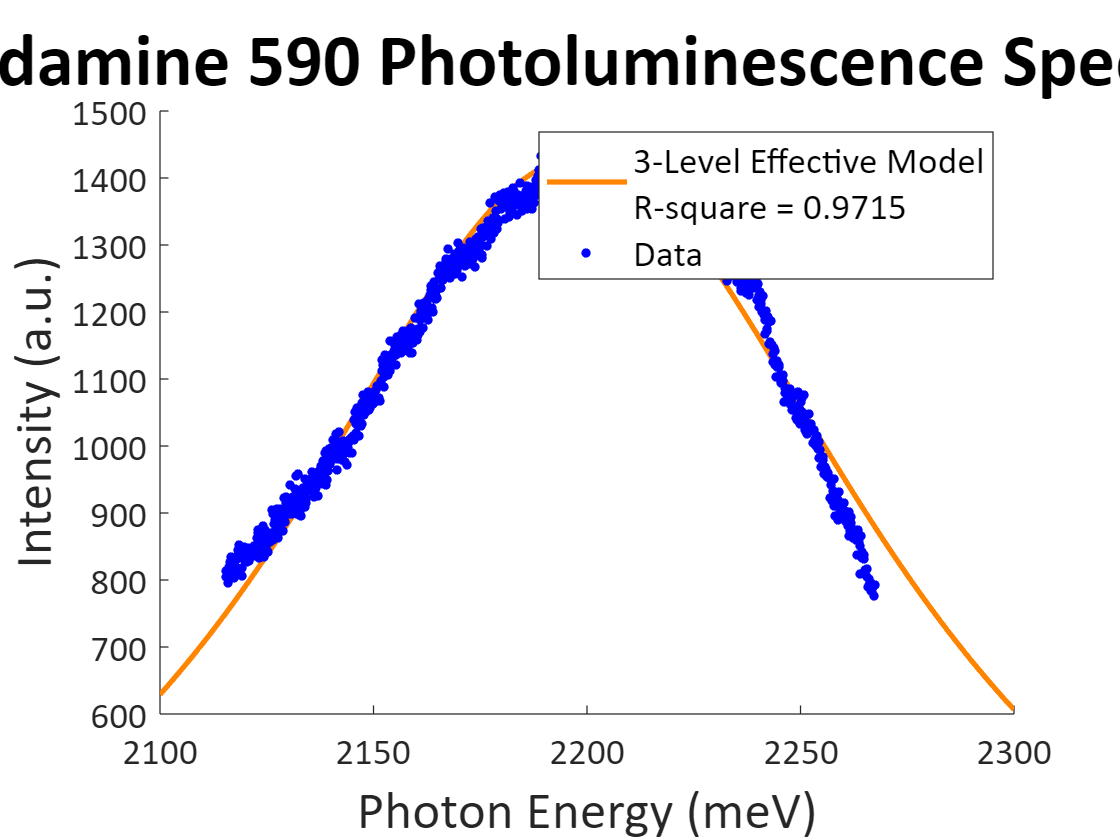

% photon energy range
Erange = [2100, 2300];
Energy = linspace(Erange(1), Erange(2), 1000);

% lower and upper bounds of fitting parameters
LowerBound = [1e3, -5, 2150];
UpperBound = [1e6, 3, 2250];
    
% choose data near the peaks
Idx = RhoData(:,1) > Erange(1) & RhoData(:,1) < Erange(2);
E_data = RhoData(Idx,1);
I_data = RhoData(Idx,2);

% make parameter bounds and loss function into a single struct variable
options.lb = LowerBound;
options.ub = UpperBound;
options.loss_type = loss_func;
    
% define fitting curve
FitModel = @(Params, Energies) Spec_3lev(Params(1), power(10, Params(2)), Params(3), Energies);
    
% iterate to find best fit
best_loss = Inf;
for it = 1:3
    options.rng_seed = it;          % Try different seeds
    Params0 = rand(1,3) .* (UpperBound - LowerBound) + LowerBound;      % try different initial parameters
    [params_i, loss_hist_i] = de_curve_fit(FitModel, E_data, I_data, Params0, options);     % differential evolution fitting
    if loss_hist_i(end) < best_loss
        best_loss = loss_hist_i(end);
        FitParams = params_i;
        loss_history = loss_hist_i;
    end
end
    
I0 = FitParams(1);
Linewidth = power(10, FitParams(2));
Ecen = FitParams(3);
    
% plot
figure;
hold on;
I_fit = Spec_3lev(I0, Linewidth, Ecen, Energy);
I_fit_sameidx = Spec_3lev(I0, Linewidth, Ecen, E_data);
Rsq = Rsqcal(I_fit_sameidx, I_data);
plot(Energy, I_fit, 'color', '#FF8500', 'LineWidth', 2);
plot(E_data, I_data, 'o', 'MarkerEdgeColor', 'blue', 'MarkerFaceColor', 'blue', 'MarkerSize', 3);
ax = gca;
ax.FontSize = 14;
ax.FontName = 'Calibri';
xlabel('Photon Energy (meV)', 'FontName', 'Calibri', 'FontSize', 20);
ylabel('Intensity (a.u.)', 'FontName', 'Calibri', 'FontSize', 20);
title('Rhodamine 590 Photoluminescence Spectrum', 'FontName', 'Calibri', 'FontSize', 28);
lg = legend({sprintf('3-Level Effective Model\nR-square = %.4f', Rsq),'Data'}, 'Location','northeast', 'FontName', 'Calibri', 'FontSize', 14);

pos = lg.Position;
% choose a point just below the legend box
x_txt = 0.900;              
y_txt = 0.800;       % tweak the 0.05 to move it closer/further
    
% show fit parameters
disp(['Loss = ', sprintf('%.4g', best_loss)]);

Loss = 1.151


disp(['I0 = ', sprintf('%.4g', I0)]);

I0 = 1.247e+05


disp(['Linewidth = ', sprintf('%.4g', Linewidth(1))]);

Linewidth = 174.4


disp(['Ecen = ', sprintf('%.4g', Ecen)]);

Ecen = 2198


## Fit & Plot Rhodamine Data to Double Gaussian Model

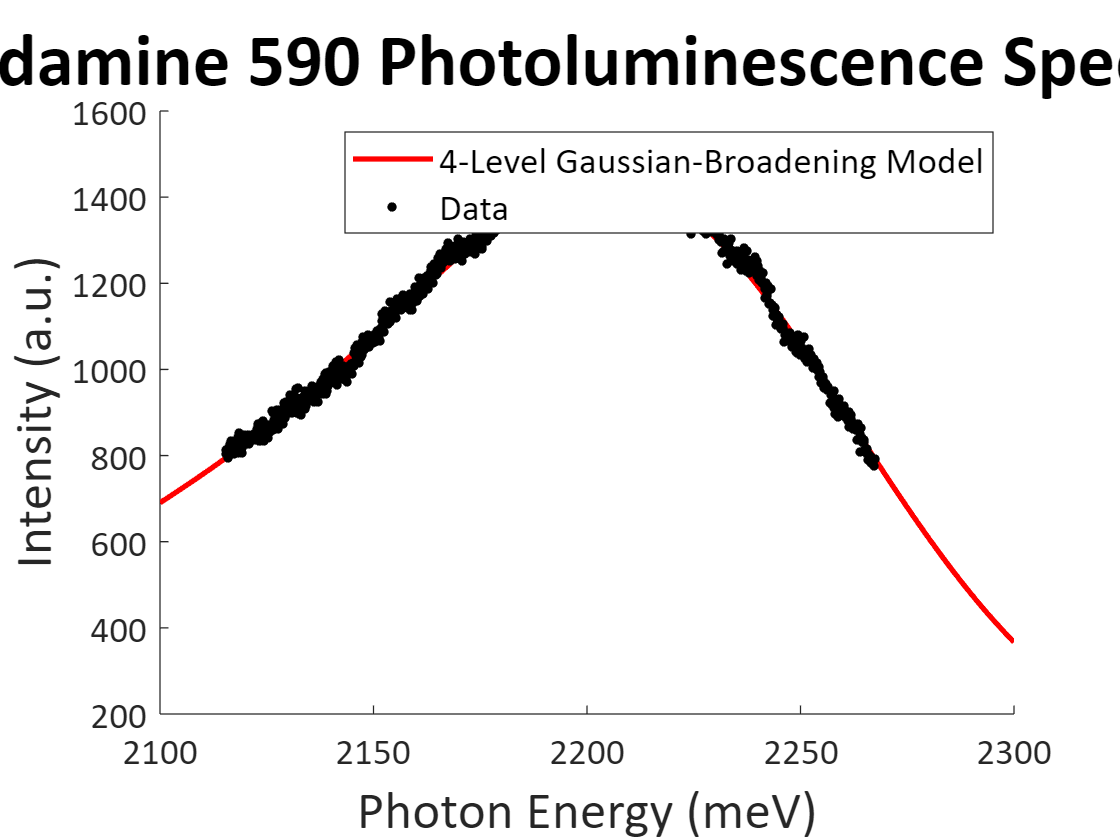

% broaden option
Broaden = 'Gauss';

% photon energy range
Erange = [2100, 2300];
Energy = linspace(Erange(1), Erange(2), 1000);

% lower and upper bounds of fitting parameters
LowerBound = [10, 0, -5, -5, 1e-2, 2150];
UpperBound = [1e6, 10, 3, 3, 1e2, 2250];

% fit data
T = 290;    % temperature
    
% choose data near the peaks
Idx = RhoData(:,1) > Erange(1) & RhoData(:,1) < Erange(2);
E_data = RhoData(Idx,1);
I_data = RhoData(Idx,2);

% make parameter bounds and loss function into a single struct variable
options.lb = LowerBound;
options.ub = UpperBound;
options.loss_type = loss_func;
    
% define fitting curve
FitModel = @(Params, Energies) Spec_4lev(Params(1), Params(2), [power(10, Params(3)), power(10, Params(4))], Params(5), Params(6), T, Energies, 'Broaden', Broaden);
    
% iterate to find best fit
best_loss = Inf;
for it = 1:3
    options.rng_seed = it;          % Try different seeds
    Params0 = rand(1,6) .* (UpperBound - LowerBound) + LowerBound;      % try different initial parameters
    [params_i, loss_hist_i] = de_curve_fit(FitModel, E_data, I_data, Params0, options);     % differential evolution fitting
    if loss_hist_i(end) < best_loss
        best_loss = loss_hist_i(end);
        FitParams = params_i;
        loss_history = loss_hist_i;
    end
end
    
% show fit parameters
I0 = FitParams(1);
TransAmpR = FitParams(2);
Linewidth = [power(10, FitParams(3)), power(10, FitParams(4))];
Delta = FitParams(5);
E1 = FitParams(6);
    
% plot
figure;
hold on;
I_fit = Spec_4lev(I0, TransAmpR, Linewidth, Delta, E1, T, Energy, 'Broaden', Broaden);
plot(Energy, I_fit, 'color', 'red', 'LineWidth', 2);
plot(E_data, I_data, 'o', 'MarkerEdgeColor', 'black', 'MarkerFaceColor', 'black', 'MarkerSize', 3);
ax = gca;
ax.FontSize = 14;
ax.FontName = 'Calibri';
xlabel('Photon Energy (meV)', 'FontName', 'Calibri', 'FontSize', 20);
ylabel('Intensity (a.u.)', 'FontName', 'Calibri', 'FontSize', 20);
title('Rhodamine 590 Photoluminescence Spectrum', 'FontName', 'Calibri', 'FontSize', 28);
legend({'4-Level Gaussian-Broadening Model','Data'}, 'Location','northeast', 'FontName', 'Calibri', 'FontSize', 14);

hold off;

% show fit parameters
disp(['Temperature = ', sprintf('%d', T), ' K']);

Temperature = 290 K


disp(['Loss = ', sprintf('%.4g', best_loss)]);

Loss = 0.2881


disp(['I0 = ', sprintf('%.4g', I0)]);

I0 = 1.678e+05


disp(['d_{20}/d_{10} = ', sprintf('%.4g', TransAmpR)]);

d_{20}/d_{10} = 2.938


disp(['Linewidths = [', sprintf('%.4g', Linewidth(1)), ', ', sprintf('%.4g', Linewidth(2)) ']']);

Linewidths = [88.43, 48.27]


disp(['Delta = ', sprintf('%.4g', Delta)]);

Delta = 66.51


disp(['E1 = ', sprintf('%.4g', E1)]);

E1 = 2150


## Fit Ruby Data to 4-Level Effective Model (T = 10K - 290K, double Lorentzian)

% photon energy range
Erange = [1785, 1795];
Energy = linspace(Erange(1), Erange(2), 1000);

% lower and upper bounds of fitting parameters
LowerBound = [2000, 0.5, -0.9, -0.8, 3.5, 1785];
UpperBound = [3400, 3, -0.2, -0.35, 4, 1795];

% variables to store fit parameters
I0 = zeros(29,1);
TransAmpR = zeros(29,1);
Linewidth = zeros(29,2);
Delta = zeros(29,1);
E1 = zeros(29,1);

% fit all 29 data
for Dnum = 1:29

    T = 10*Dnum;    % temperature
    
    % choose data near the peaks
    Idx = RubyData{Dnum}(:,1) > Erange(1) & RubyData{Dnum}(:,1) < Erange(2);
    E_data = RubyData{Dnum}(Idx,1);
    I_data = RubyData{Dnum}(Idx,2);
    
    % make parameter bounds and loss function into a single struct variable
    options.lb = LowerBound;
    options.ub = UpperBound;
    options.loss_type = loss_func;
    
    % define fitting curve
    FitModel = @(Params, Energies) Spec_4lev(Params(1), Params(2), [power(10, Params(3)), power(10, Params(4))], Params(5), Params(6), T, Energies);
    
    % iterate to find best fit
    best_loss = Inf;
    for it = 1:3
        options.rng_seed = it;          % Try different seeds
        Params0 = rand(1,6) .* (UpperBound - LowerBound) + LowerBound;      % try different initial parameters
        [params_i, loss_hist_i] = de_curve_fit(FitModel, E_data, I_data, Params0, options);     % differential evolution fitting
        if loss_hist_i(end) < best_loss
            best_loss = loss_hist_i(end);
            FitParams = params_i;
            loss_history = loss_hist_i;
        end
    end

    I0(Dnum) = FitParams(1);
    TransAmpR(Dnum) = FitParams(2);
    Linewidth(Dnum,:) = [power(10, FitParams(3)), power(10, FitParams(4))];
    Delta(Dnum) = FitParams(5);
    E1(Dnum) = FitParams(6);

    % show message
    disptime(['Data #', sprintf('%d', Dnum), ' | loss = ', sprintf('%.4g', best_loss)]);

end

25-06-10 11:02:24 | Data #1 | loss = 49.98
25-06-10 11:02:28 | Data #2 | loss = 43.87
25-06-10 11:02:33 | Data #3 | loss = 39.89
25-06-10 11:02:37 | Data #4 | loss = 39.45
25-06-10 11:02:41 | Data #5 | loss = 30.66
25-06-10 11:02:46 | Data #6 | loss = 27.68
25-06-10 11:02:58 | Data #7 | loss = 25.03
25-06-10 11:03:10 | Data #8 | loss = 20.75
25-06-10 11:03:23 | Data #9 | loss = 20.75
25-06-10 11:03:35 | Data #10 | loss = 13.79
25-06-10 11:03:48 | Data #11 | loss = 16.85
25-06-10 11:04:01 | Data #12 | loss = 18.88
25-06-10 11:04:12 | Data #13 | loss = 17.28
25-06-10 11:04:21 | Data #14 | loss = 17.82
25-06-10 11:04:25 | Data #15 | loss = 17.82
25-06-10 11:04:29 | Data #16 | loss = 20.43
25-06-10 11:04:35 | Data #17 | loss = 23.6
25-06-10 11:04:49 | Data #18 | loss = 21.36
25-06-10 11:05:02 | Data #19 | loss = 7.19
25-06-10 11:05:14 | Data #20 | loss = 21.98
25-06-10 11:05:27 | Data #21 | loss = 20.05
25-06-10 11:05:39 | Data #22 | loss = 25.05
25-06-10 11:05:49 | Data #23 | loss = 8.6
2

## Plot Ruby Data with Fit Curve

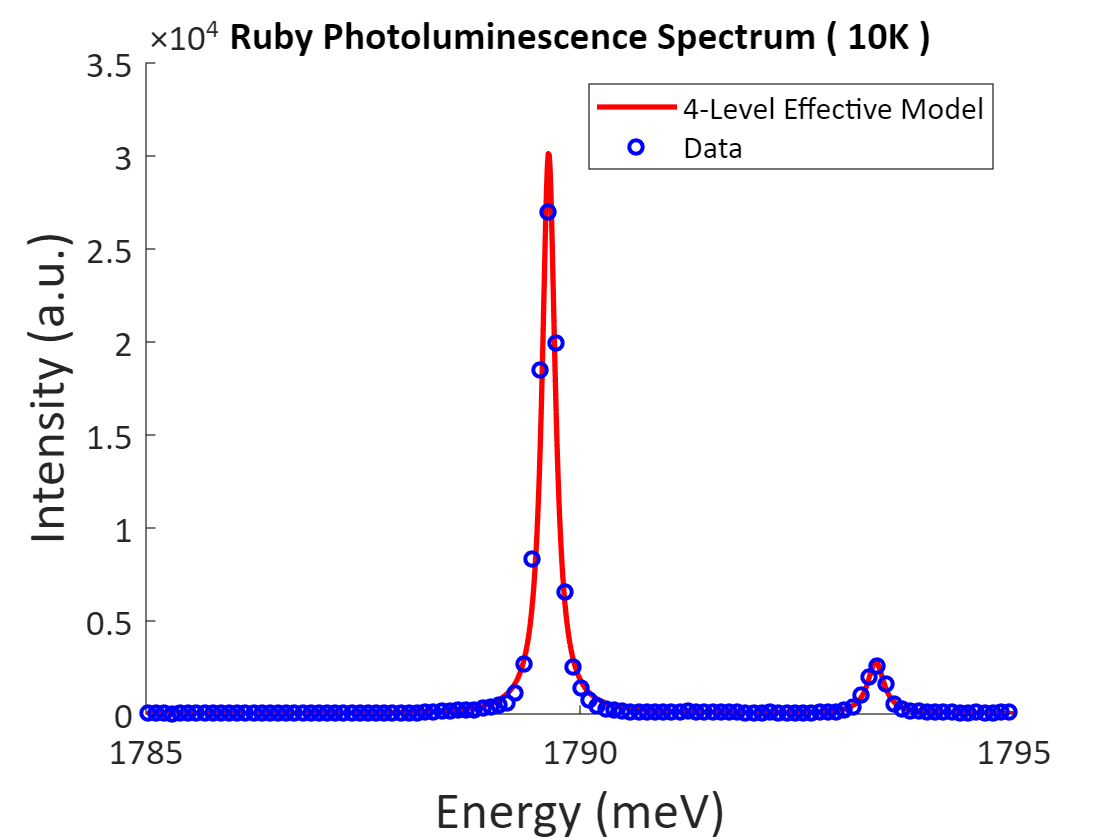

Fit Parameters :


T = 10 K


I0 = 2800


d_{20}/d_{10} = 2.994


Linewidths = [0.1855, 0.2272]


Delta = 3.768


E1 = 1790


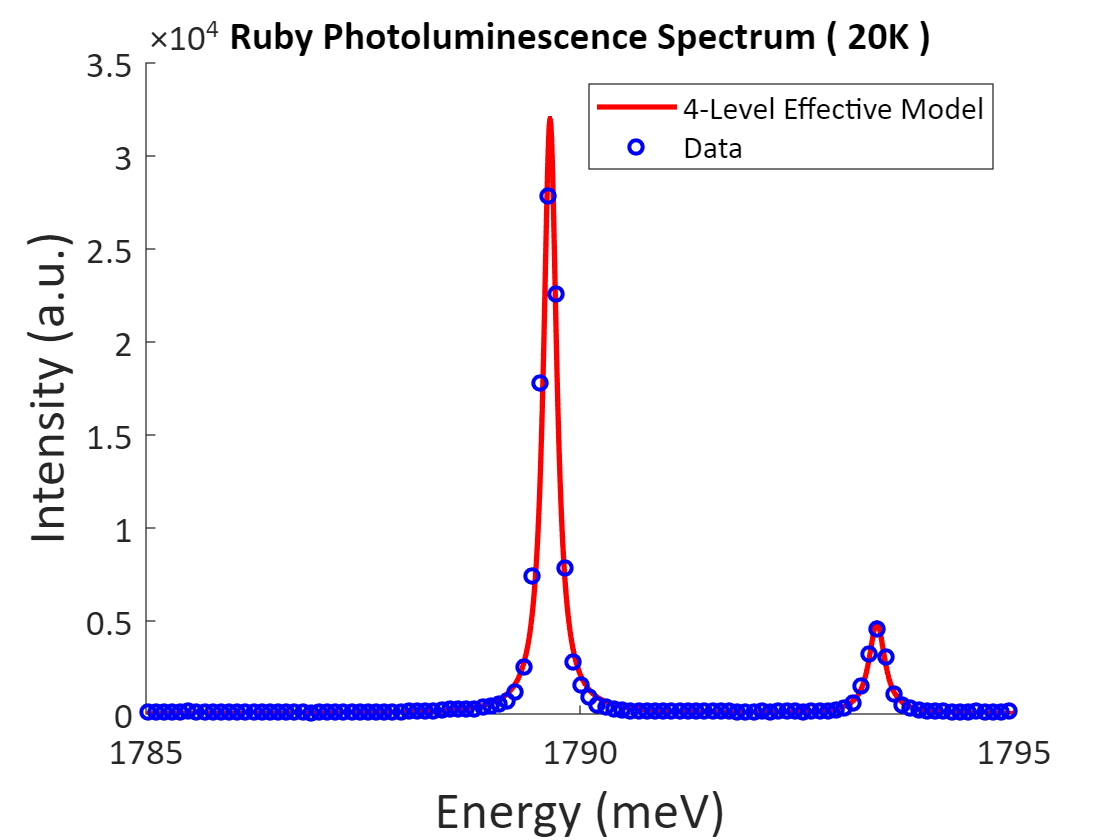

Fit Parameters :


T = 20 K


I0 = 2960


d_{20}/d_{10} = 1.274


Linewidths = [0.1849, 0.2209]


Delta = 3.765


E1 = 1790


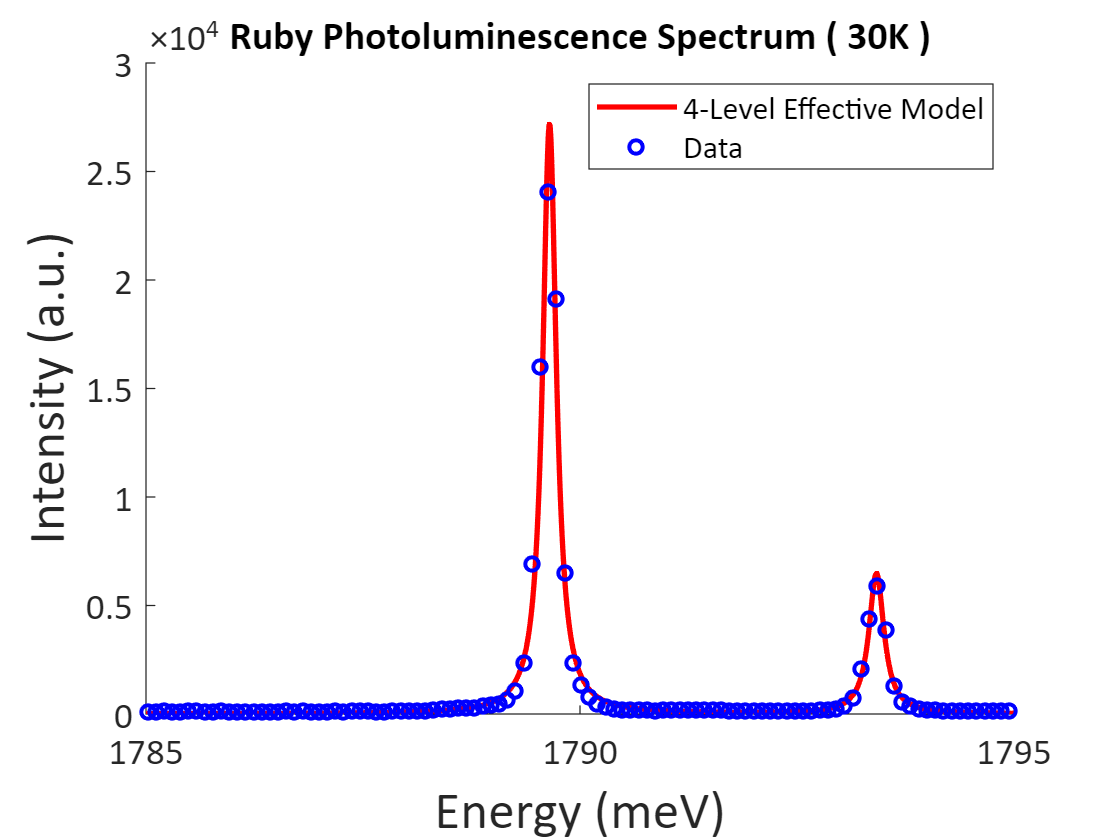

Fit Parameters :


T = 30 K


I0 = 2589


d_{20}/d_{10} = 1.065


Linewidths = [0.1902, 0.2111]


Delta = 3.767


E1 = 1790


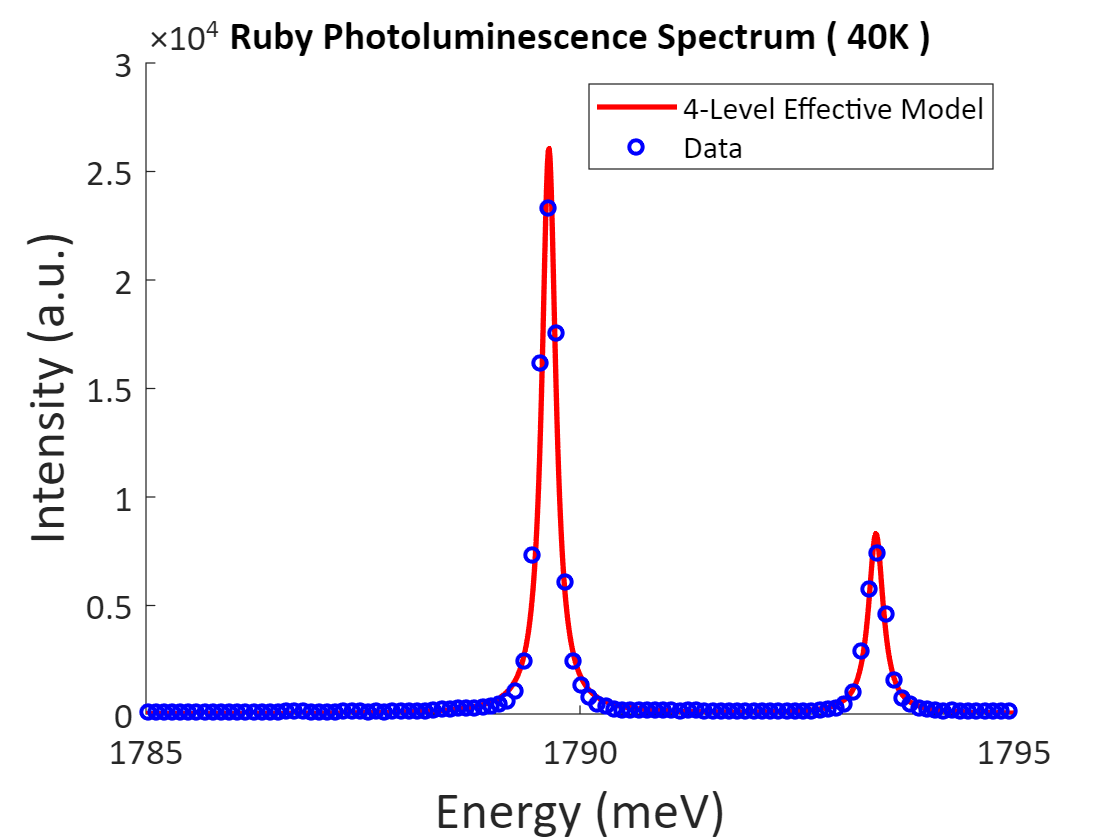

Fit Parameters :


T = 40 K


I0 = 2533


d_{20}/d_{10} = 1.008


Linewidths = [0.1942, 0.2076]


Delta = 3.768


E1 = 1790


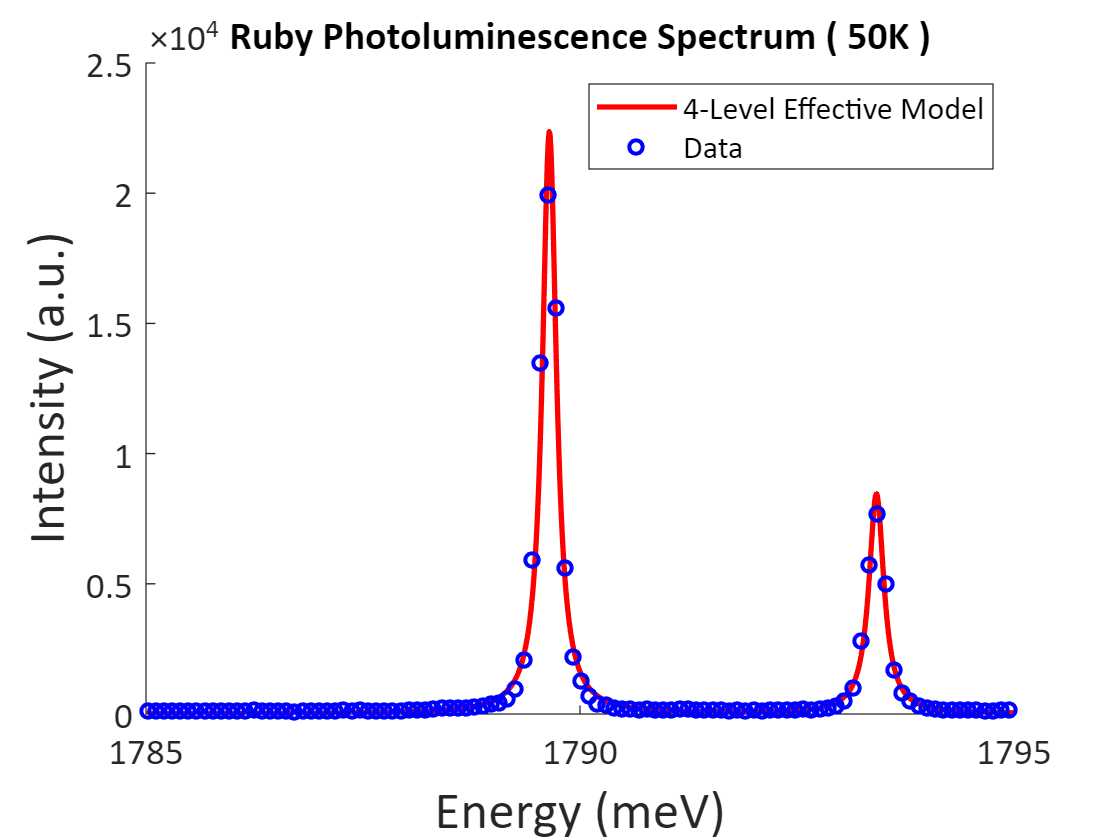

Fit Parameters :


T = 50 K


I0 = 2208


d_{20}/d_{10} = 0.9836


Linewidths = [0.1974, 0.2109]


Delta = 3.768


E1 = 1790


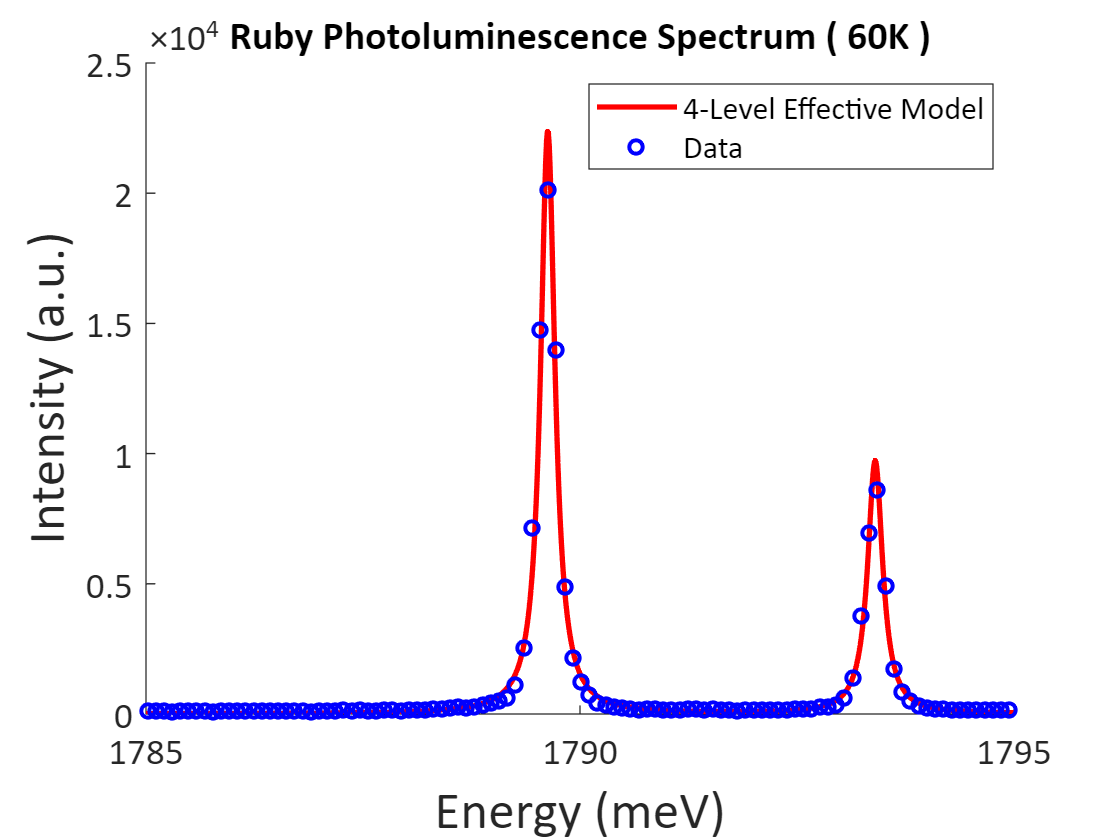

Fit Parameters :


T = 60 K


I0 = 2259


d_{20}/d_{10} = 0.968


Linewidths = [0.2016, 0.2098]


Delta = 3.772


E1 = 1790


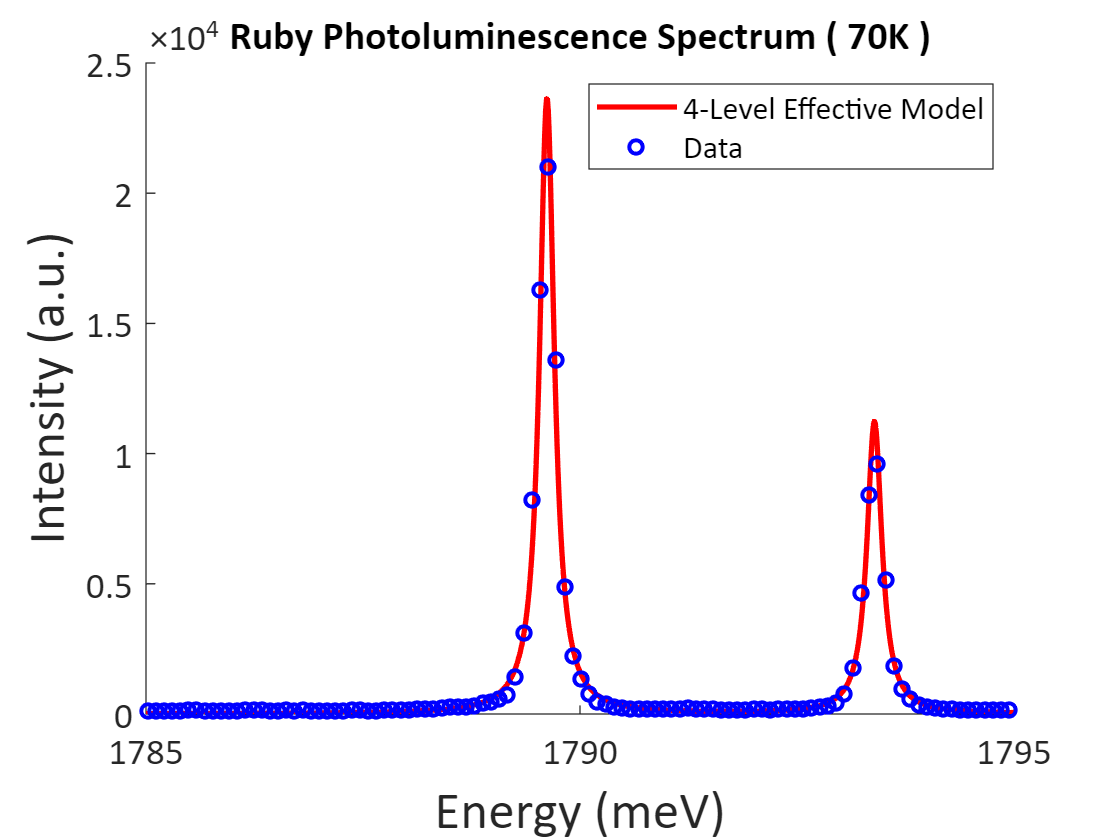

Fit Parameters :


T = 70 K


I0 = 2431


d_{20}/d_{10} = 0.9485


Linewidths = [0.2054, 0.2082]


Delta = 3.773


E1 = 1790


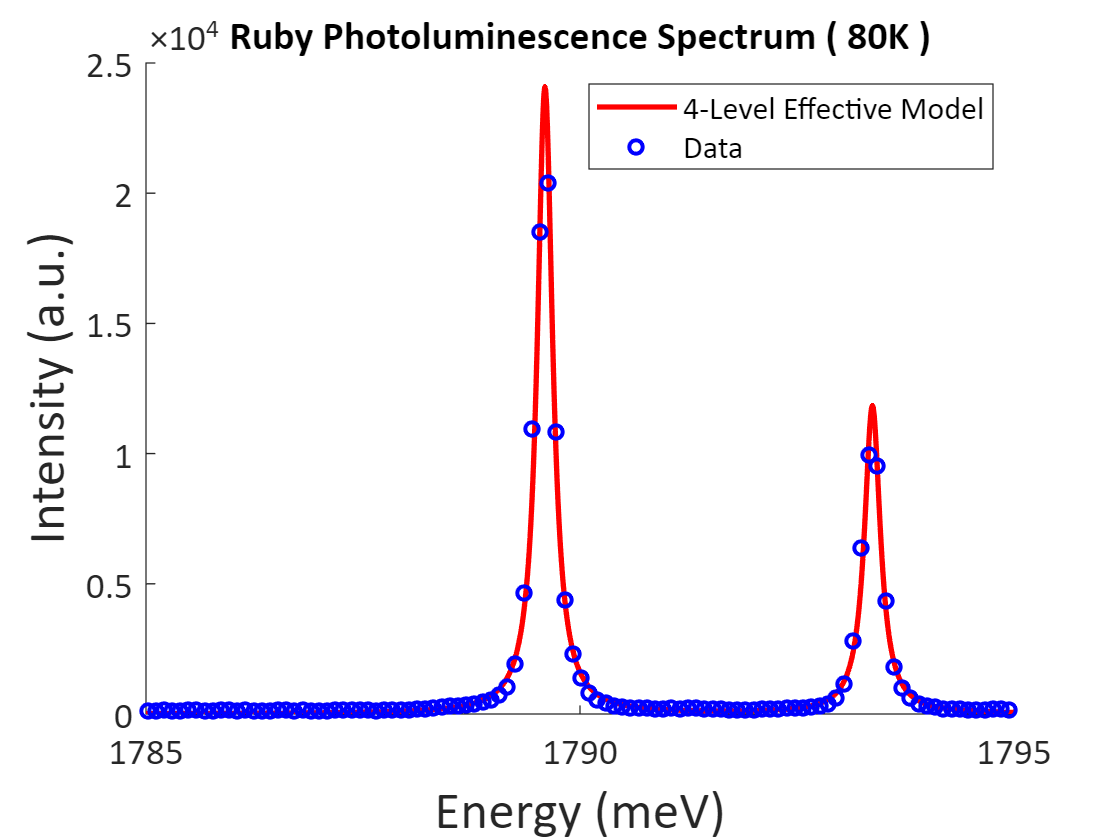

Fit Parameters :


T = 80 K


I0 = 2588


d_{20}/d_{10} = 0.9376


Linewidths = [0.2149, 0.2226]


Delta = 3.772


E1 = 1790


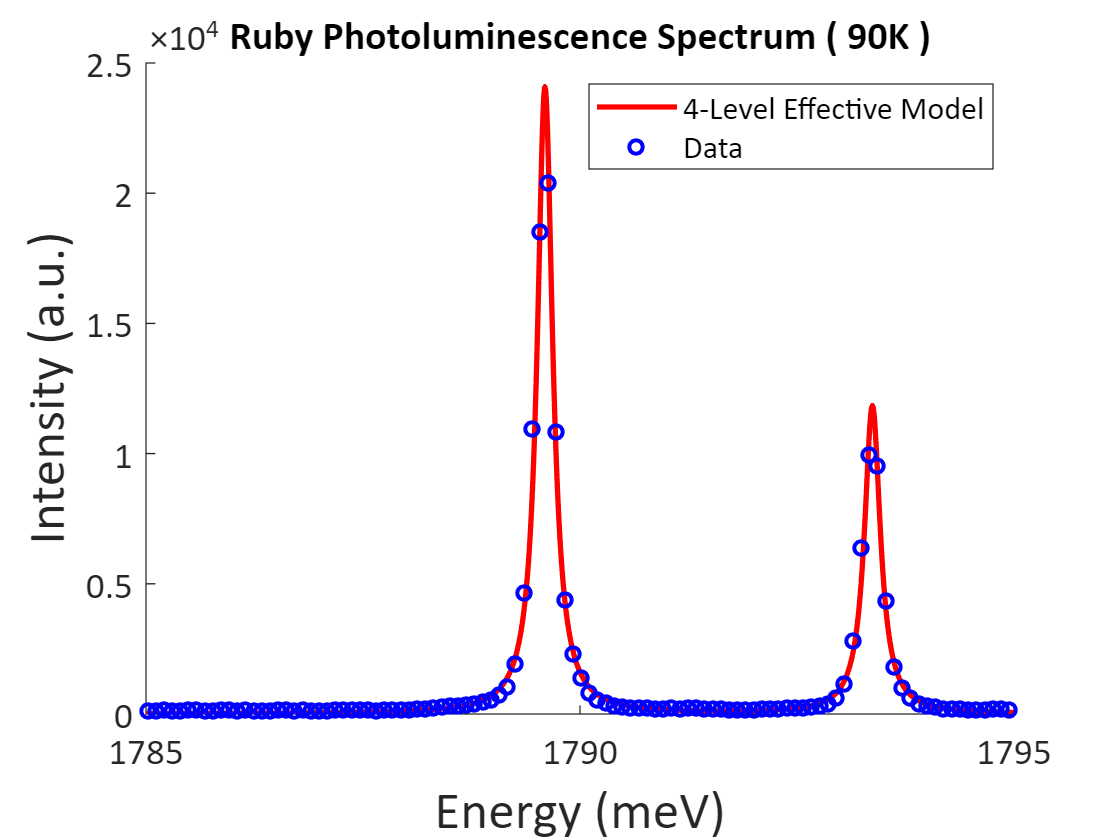

Fit Parameters :


T = 90 K


I0 = 2588


d_{20}/d_{10} = 0.9095


Linewidths = [0.2149, 0.2226]


Delta = 3.772


E1 = 1790


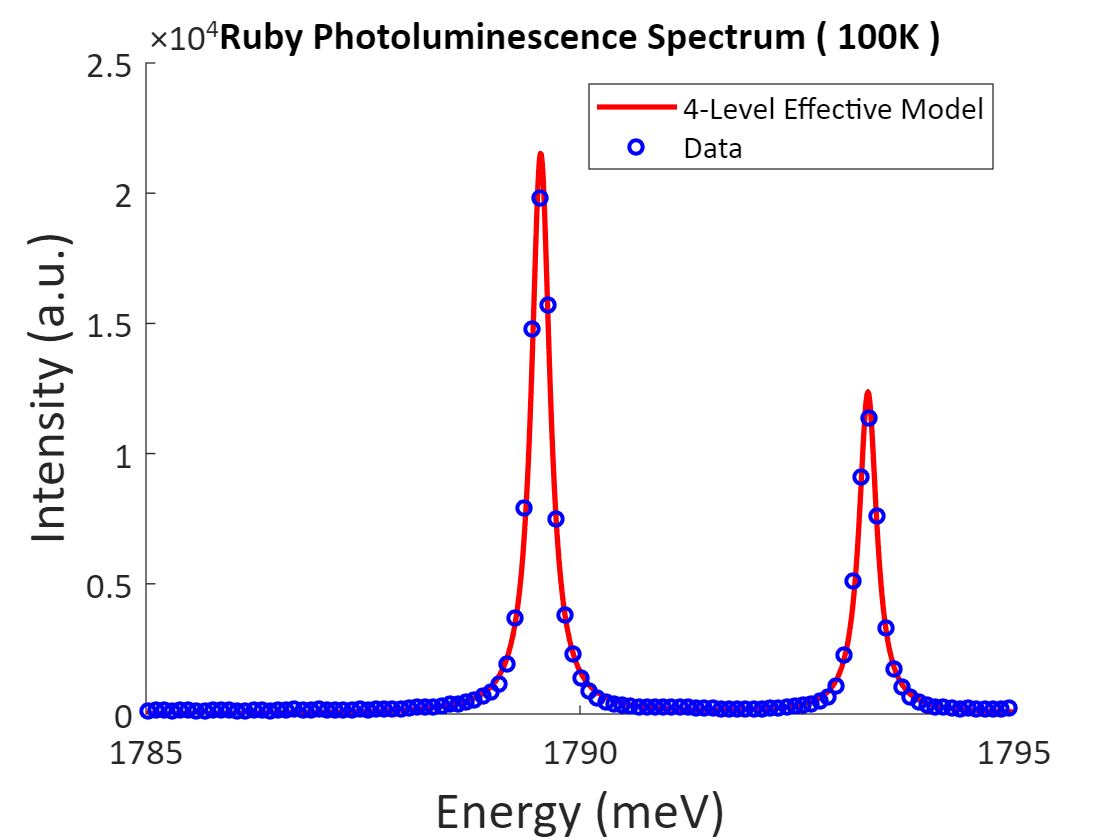

Fit Parameters :


T = 100 K


I0 = 2781


d_{20}/d_{10} = 0.9217


Linewidths = [0.2583, 0.2471]


Delta = 3.77


E1 = 1790


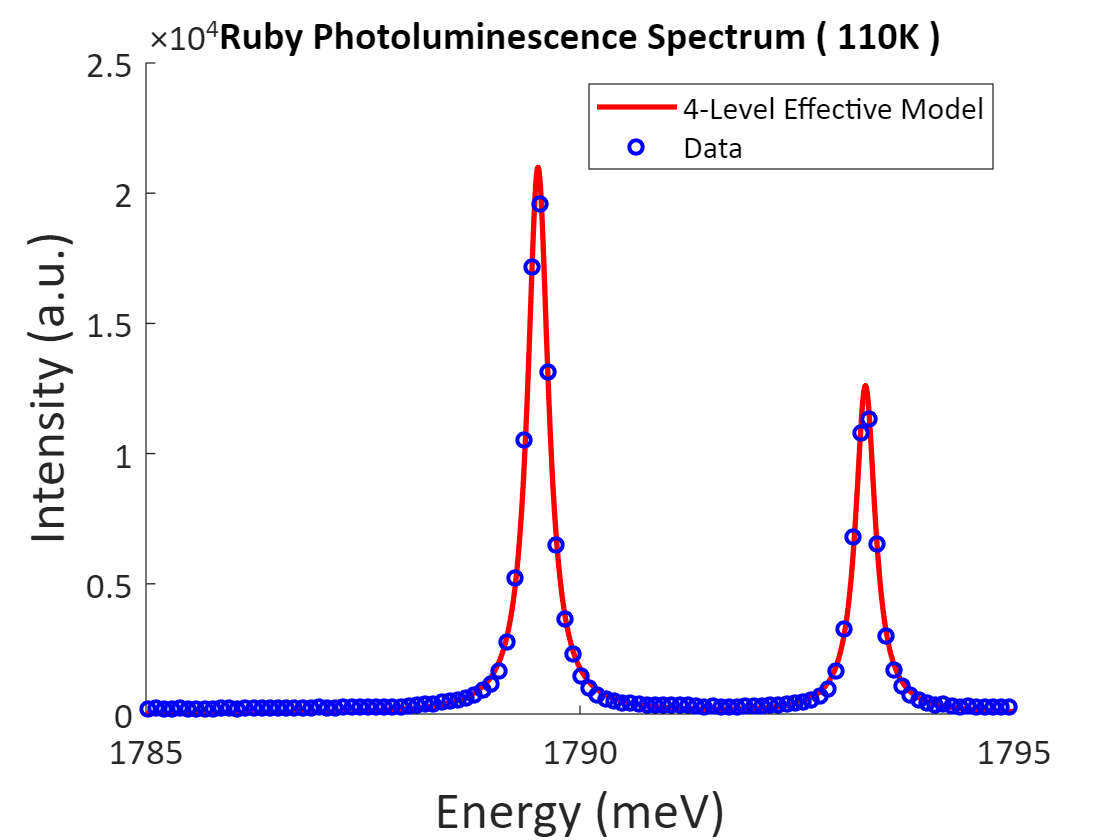

Fit Parameters :


T = 110 K


I0 = 3048


d_{20}/d_{10} = 0.9199


Linewidths = [0.2904, 0.2752]


Delta = 3.772


E1 = 1790


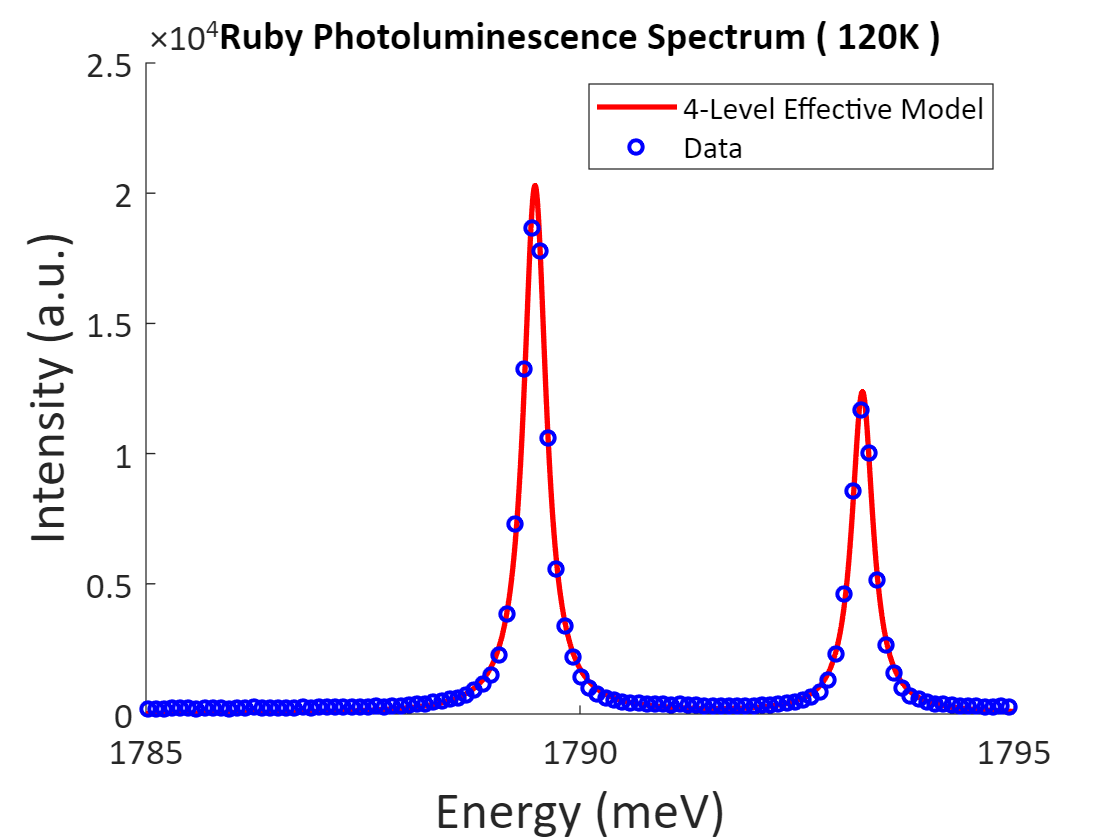

Fit Parameters :


T = 120 K


I0 = 3196


d_{20}/d_{10} = 0.9083


Linewidths = [0.315, 0.2962]


Delta = 3.772


E1 = 1789


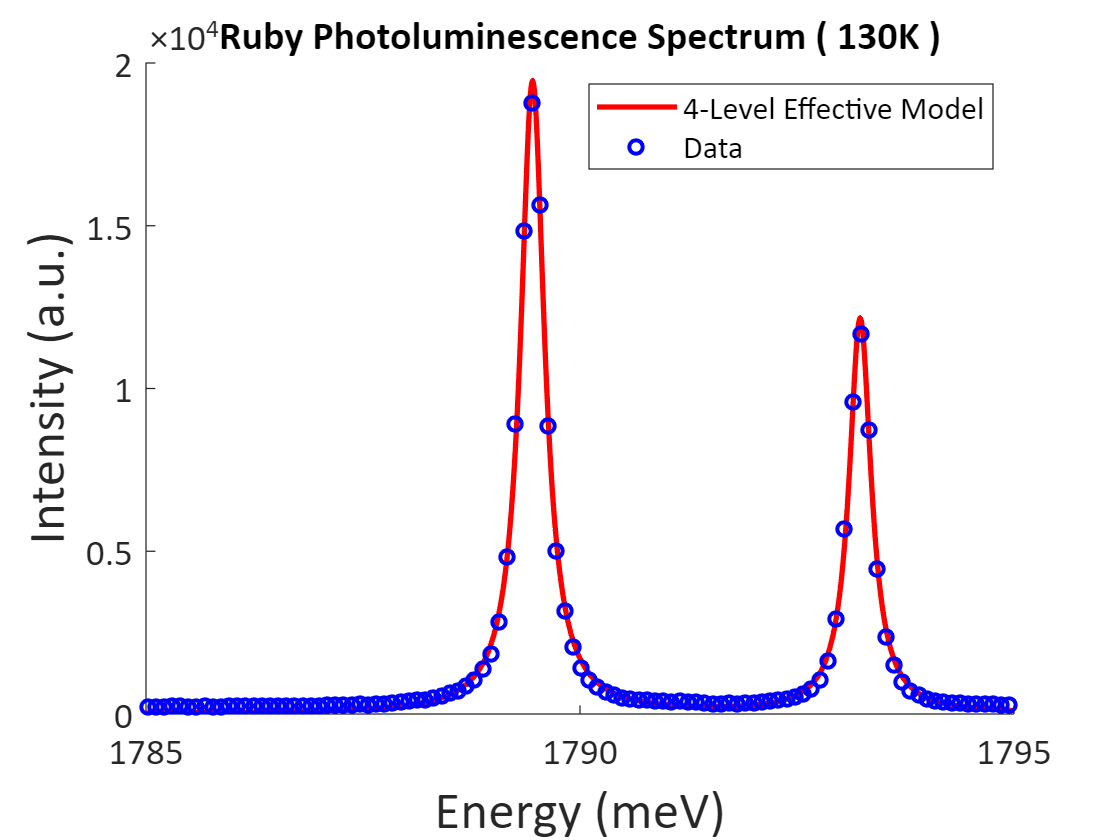

Fit Parameters :


T = 130 K


I0 = 3265


d_{20}/d_{10} = 0.8972


Linewidths = [0.3359, 0.3093]


Delta = 3.774


E1 = 1789


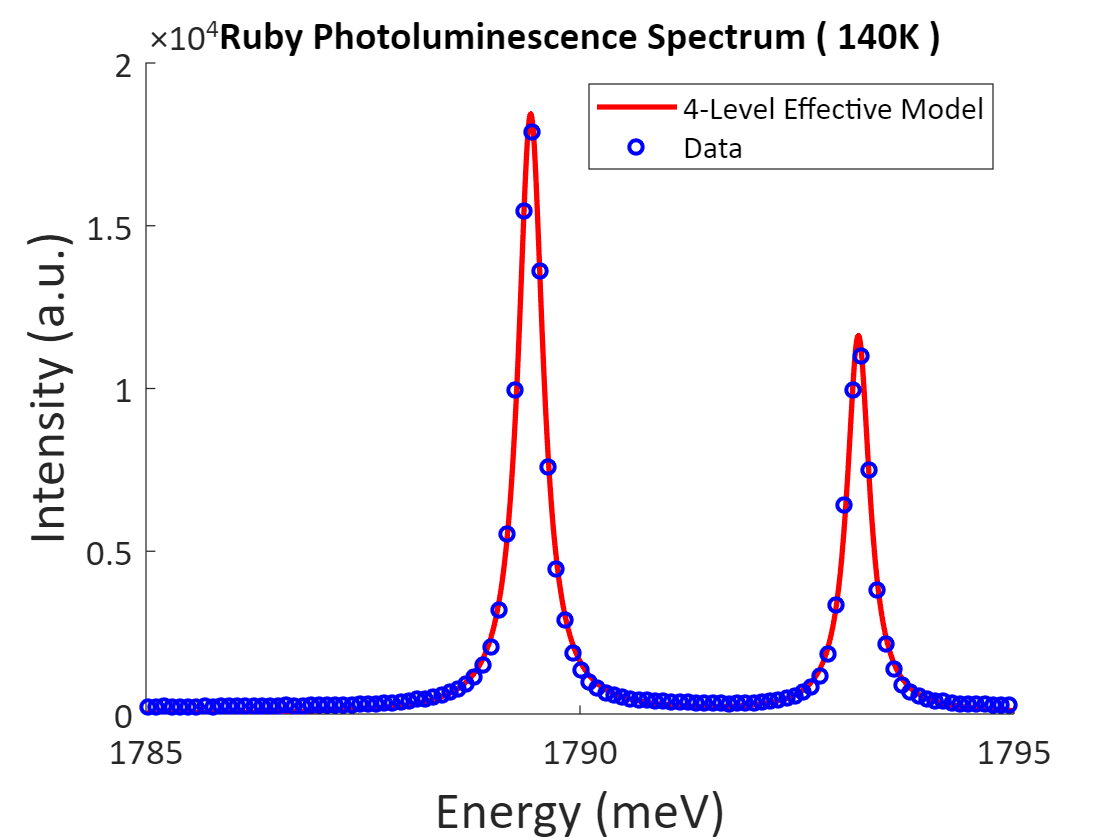

Fit Parameters :


T = 140 K


I0 = 3215


d_{20}/d_{10} = 0.8872


Linewidths = [0.349, 0.3191]


Delta = 3.775


E1 = 1789


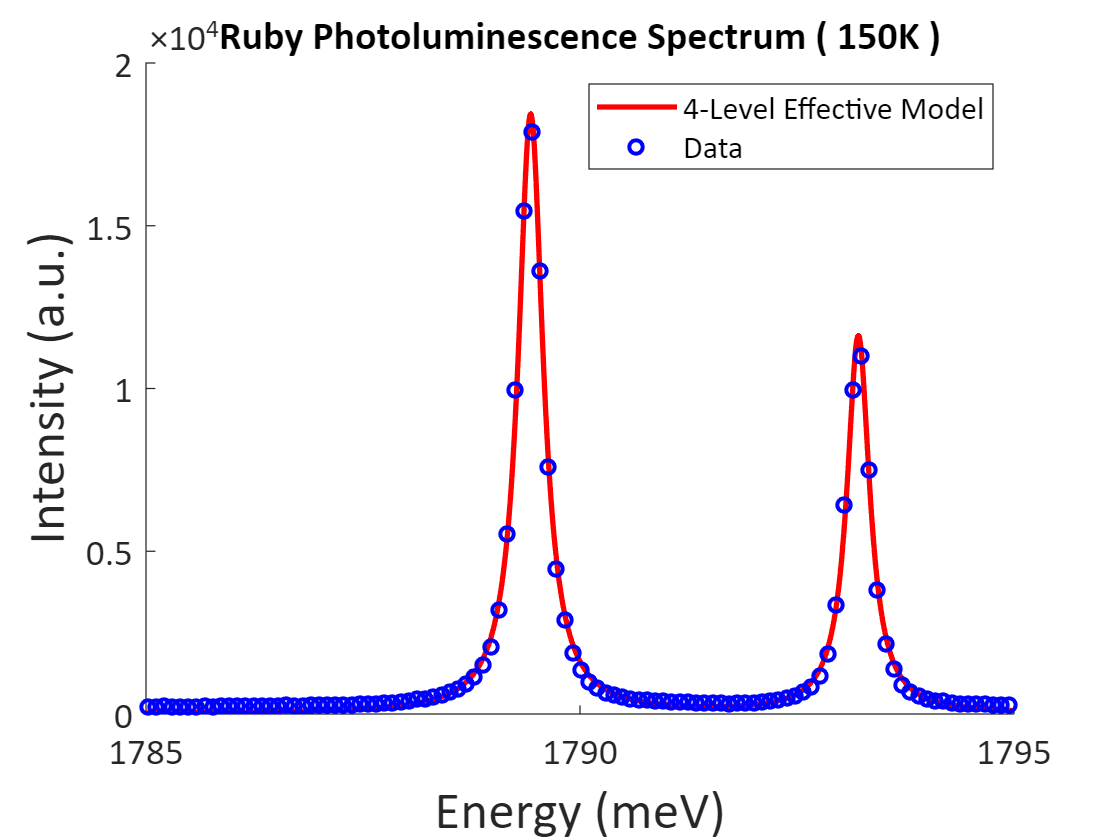

Fit Parameters :


T = 150 K


I0 = 3215


d_{20}/d_{10} = 0.878


Linewidths = [0.349, 0.3191]


Delta = 3.775


E1 = 1789


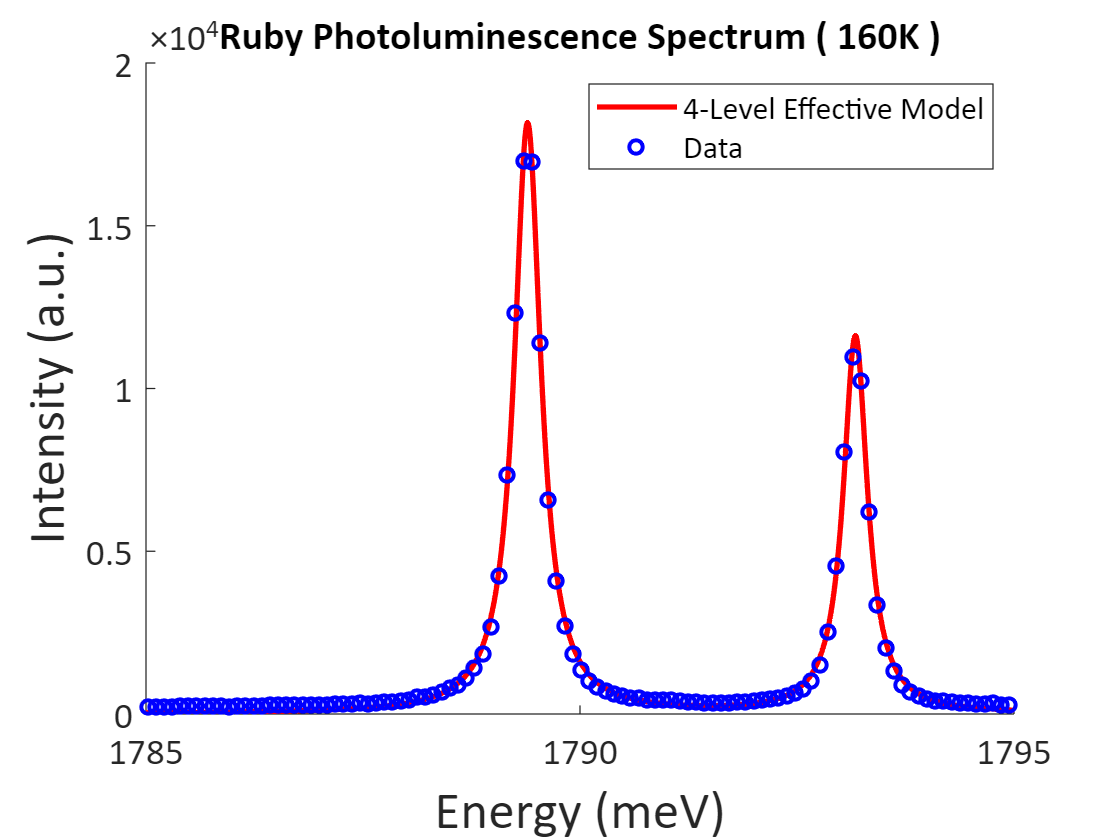

Fit Parameters :


T = 160 K


I0 = 3380


d_{20}/d_{10} = 0.8728


Linewidths = [0.3725, 0.3379]


Delta = 3.777


E1 = 1789


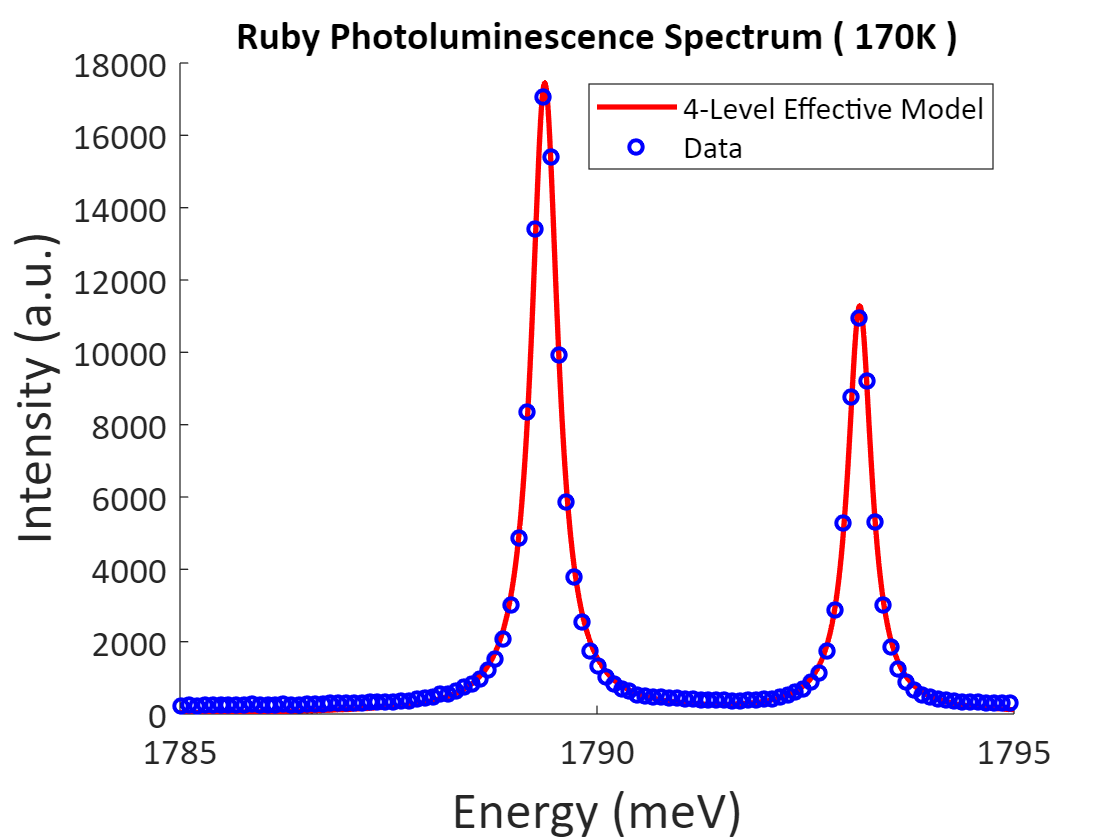

Fit Parameters :


T = 170 K


I0 = 3385


d_{20}/d_{10} = 0.8657


Linewidths = [0.3885, 0.3488]


Delta = 3.777


E1 = 1789


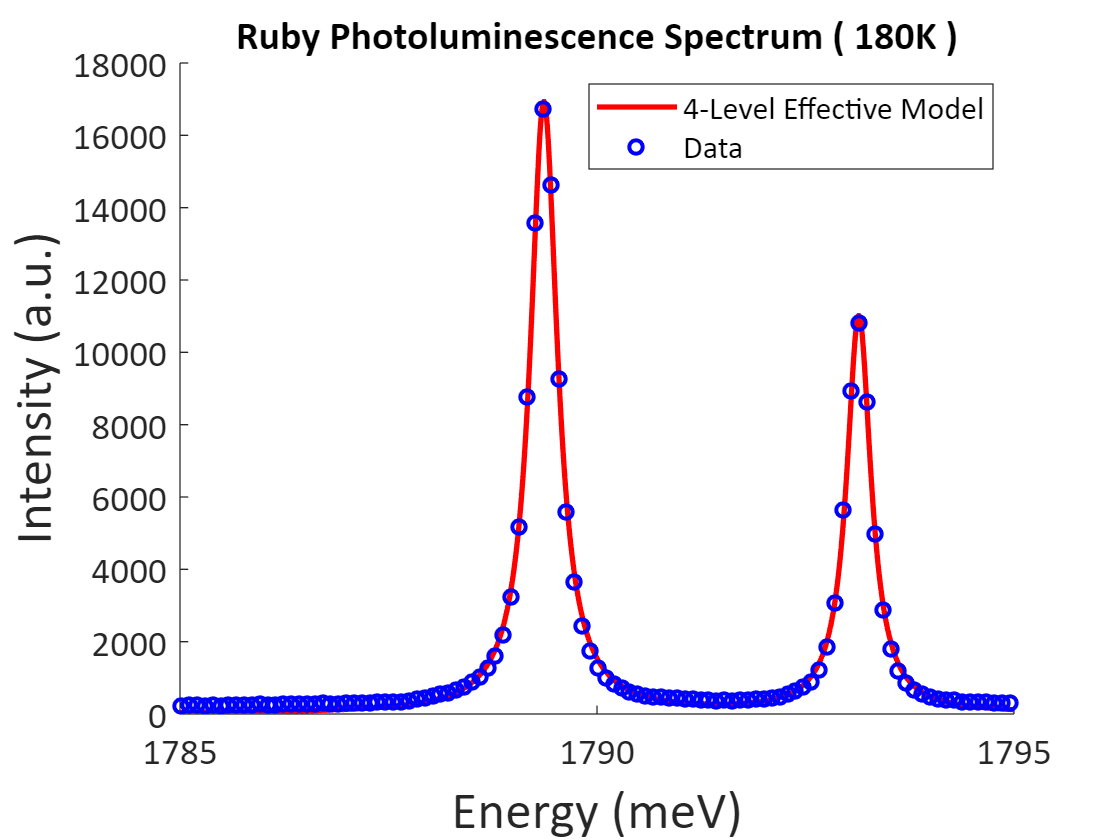

Fit Parameters :


T = 180 K


I0 = 3364


d_{20}/d_{10} = 0.8608


Linewidths = [0.3977, 0.3558]


Delta = 3.776


E1 = 1789


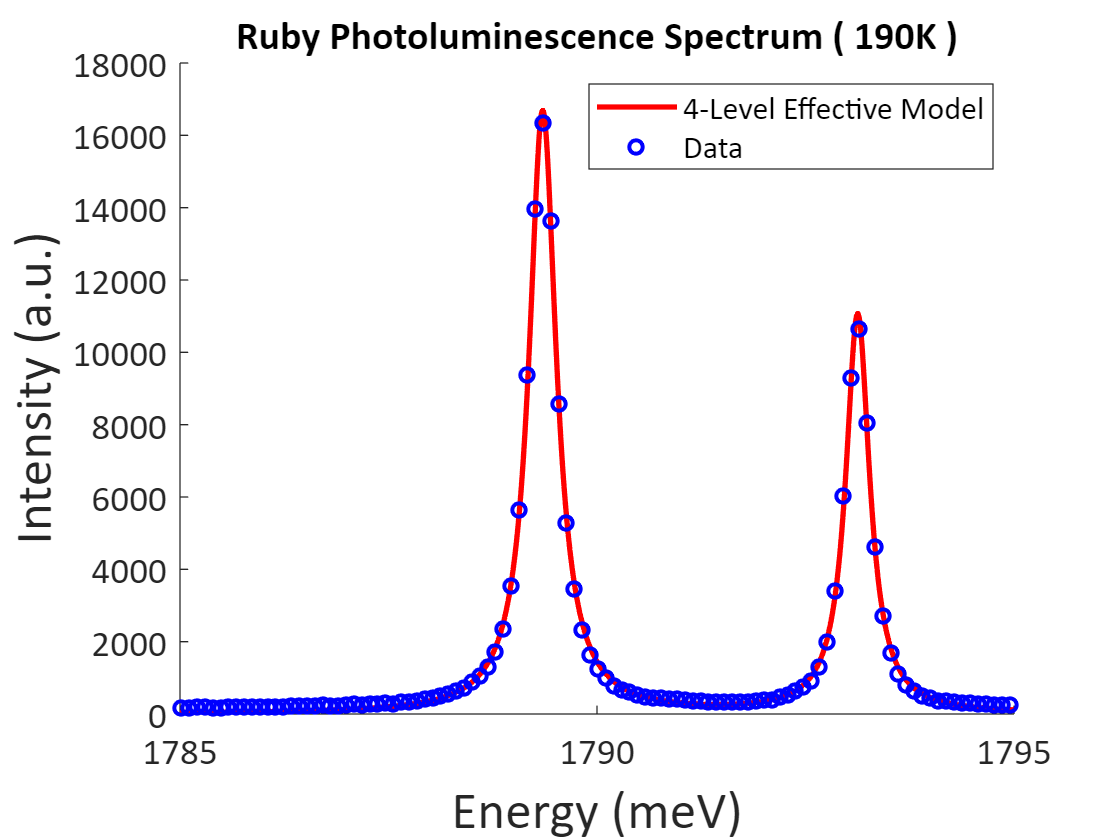

Fit Parameters :


T = 190 K


I0 = 3308


d_{20}/d_{10} = 0.8546


Linewidths = [0.3968, 0.3478]


Delta = 3.777


E1 = 1789


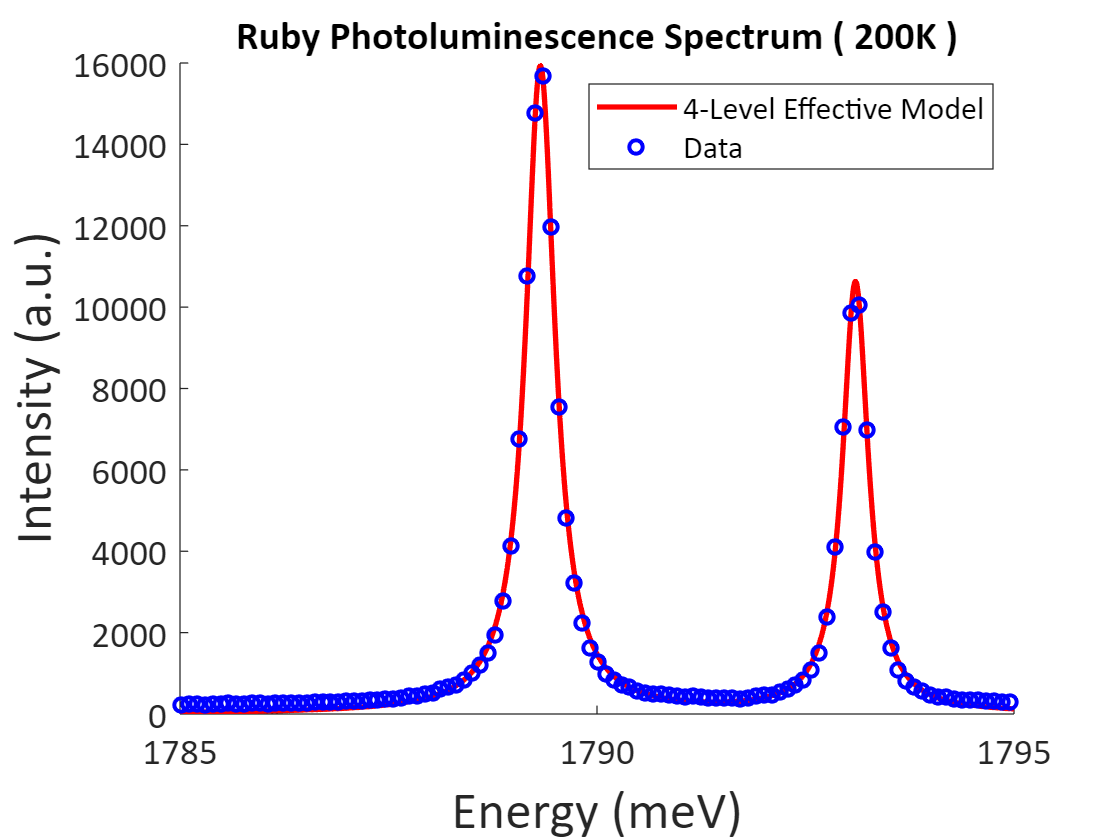

Fit Parameters :


T = 200 K


I0 = 3400


d_{20}/d_{10} = 0.8534


Linewidths = [0.4274, 0.3756]


Delta = 3.778


E1 = 1789


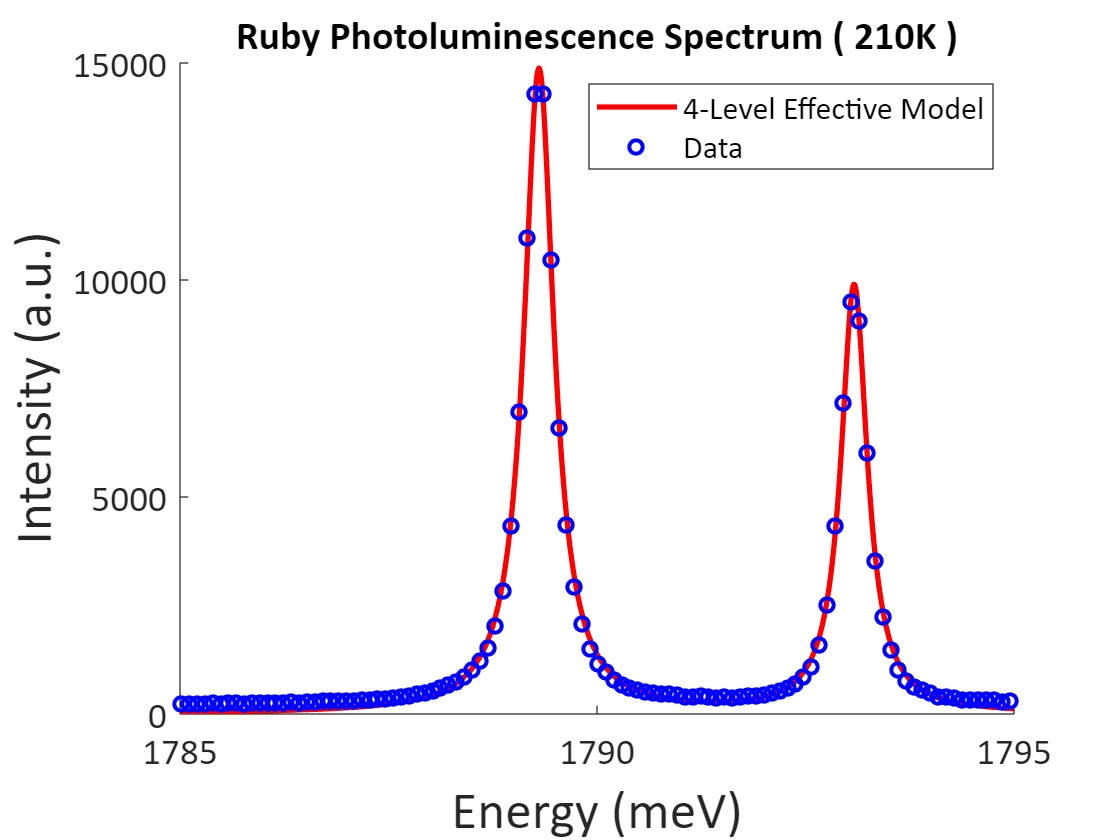

Fit Parameters :


T = 210 K


I0 = 3253


d_{20}/d_{10} = 0.8468


Linewidths = [0.4379, 0.3841]


Delta = 3.779


E1 = 1789


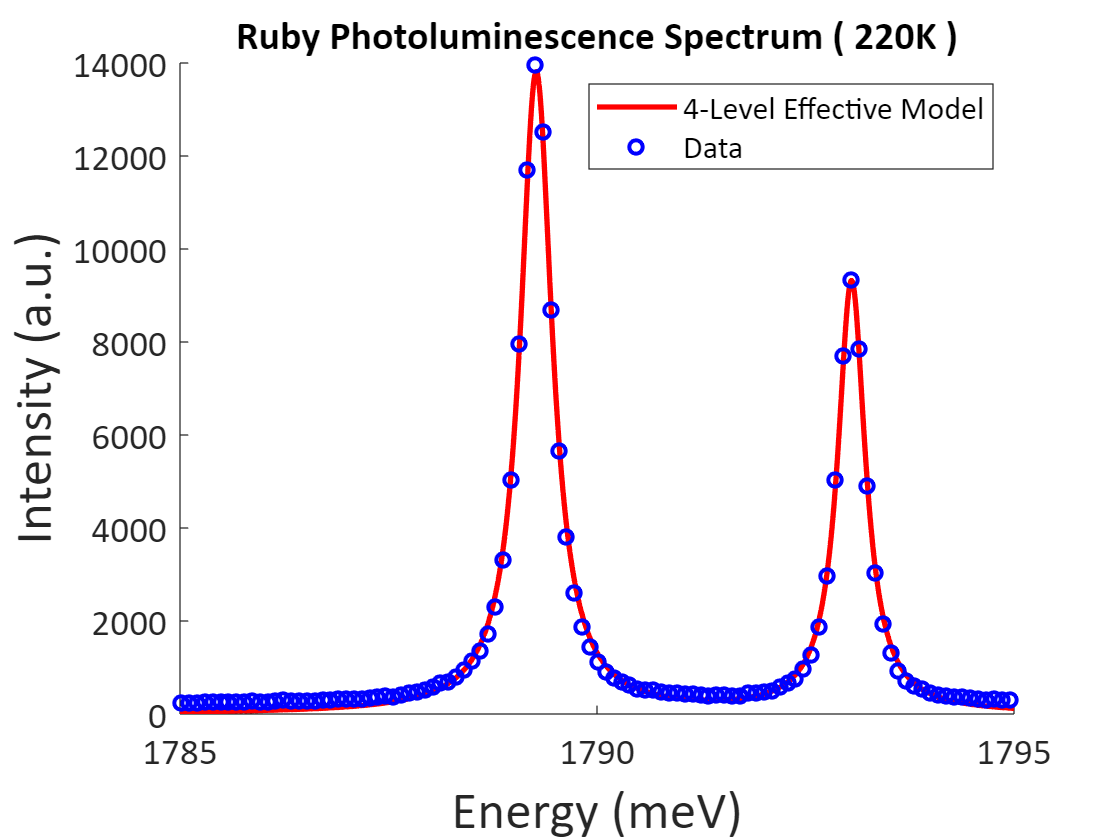

Fit Parameters :


T = 220 K


I0 = 3214


d_{20}/d_{10} = 0.8429


Linewidths = [0.4661, 0.4033]


Delta = 3.781


E1 = 1789


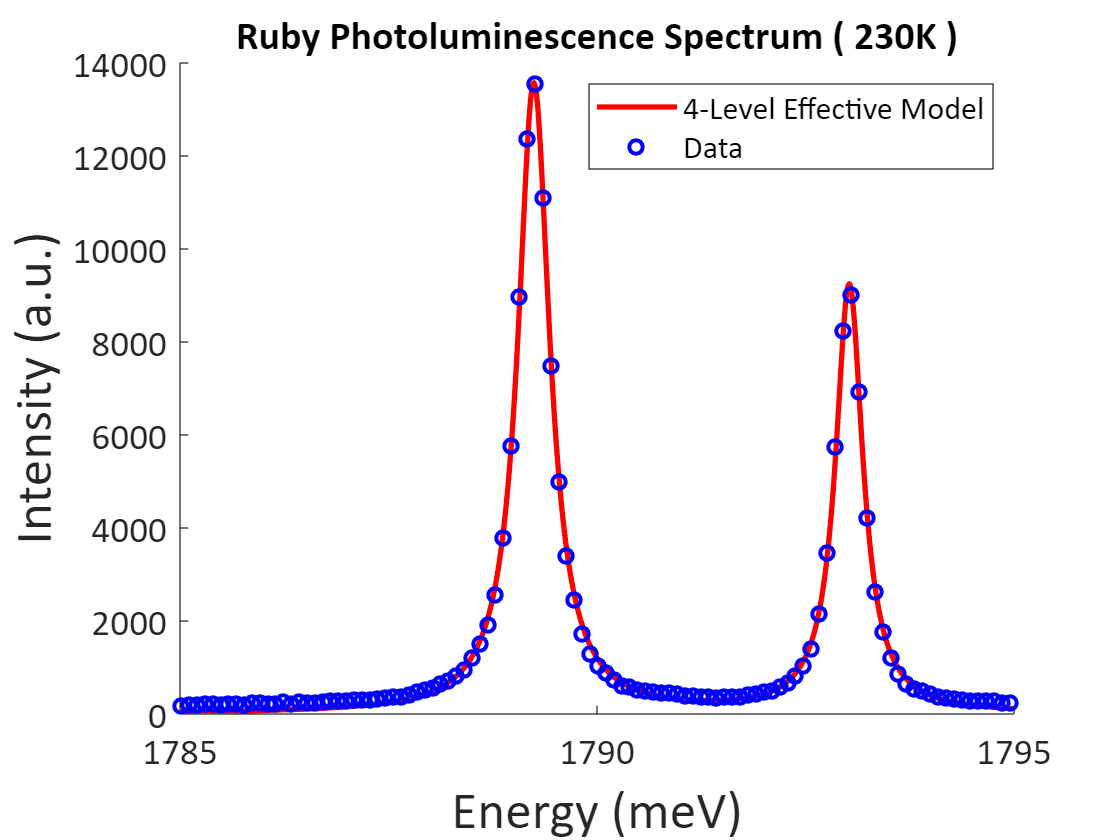

Fit Parameters :


T = 230 K


I0 = 3151


d_{20}/d_{10} = 0.8388


Linewidths = [0.4652, 0.3981]


Delta = 3.782


E1 = 1789


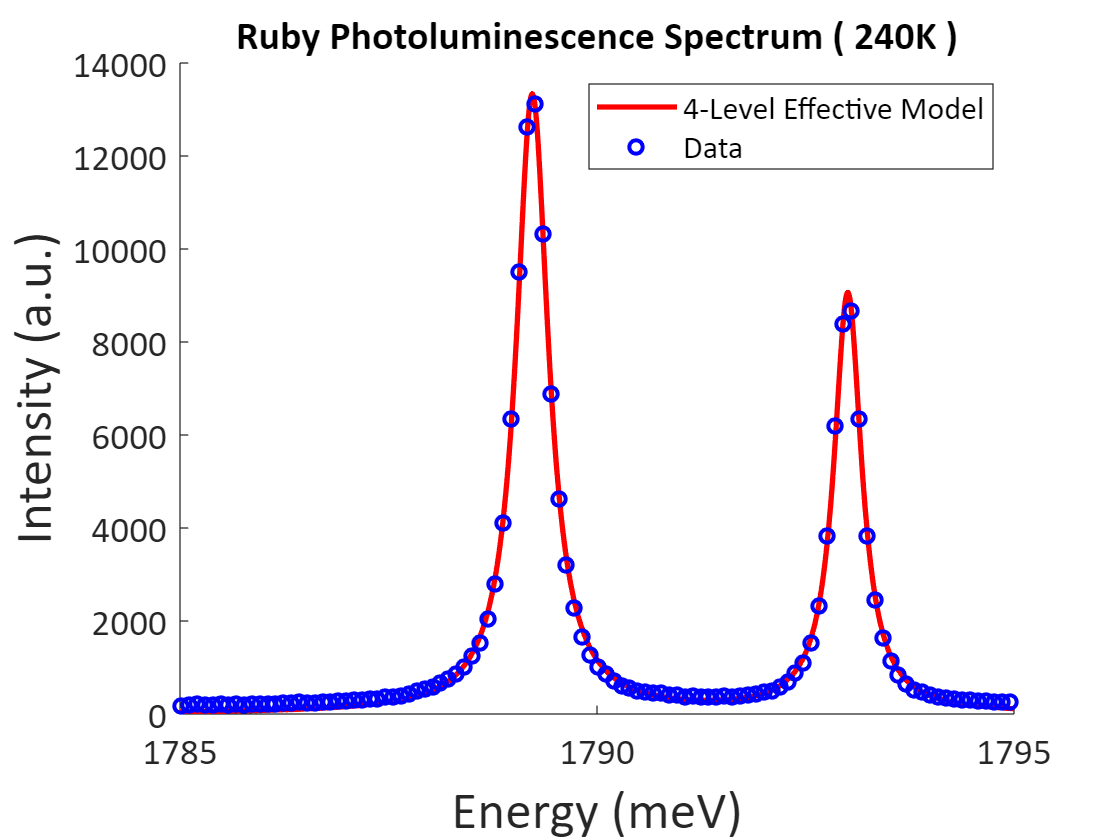

Fit Parameters :


T = 240 K


I0 = 3140


d_{20}/d_{10} = 0.8356


Linewidths = [0.4718, 0.4049]


Delta = 3.783


E1 = 1789


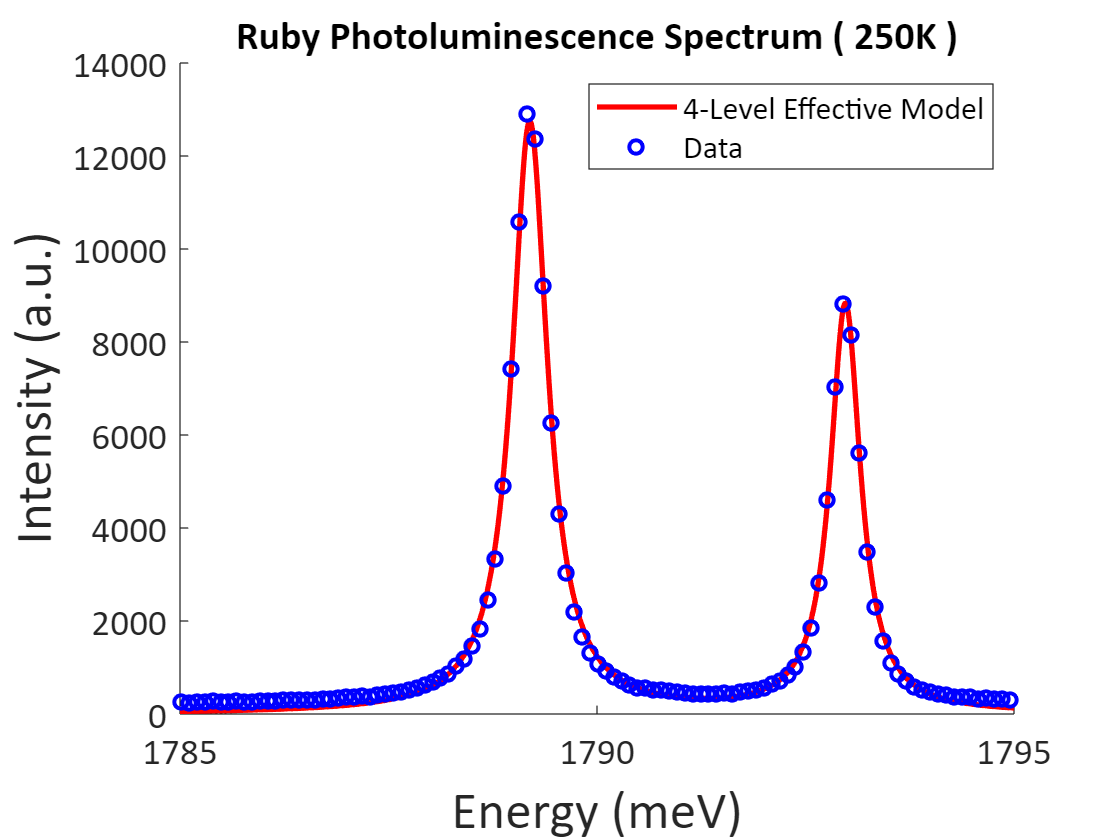

Fit Parameters :


T = 250 K


I0 = 3302


d_{20}/d_{10} = 0.8354


Linewidths = [0.519, 0.4403]


Delta = 3.785


E1 = 1789


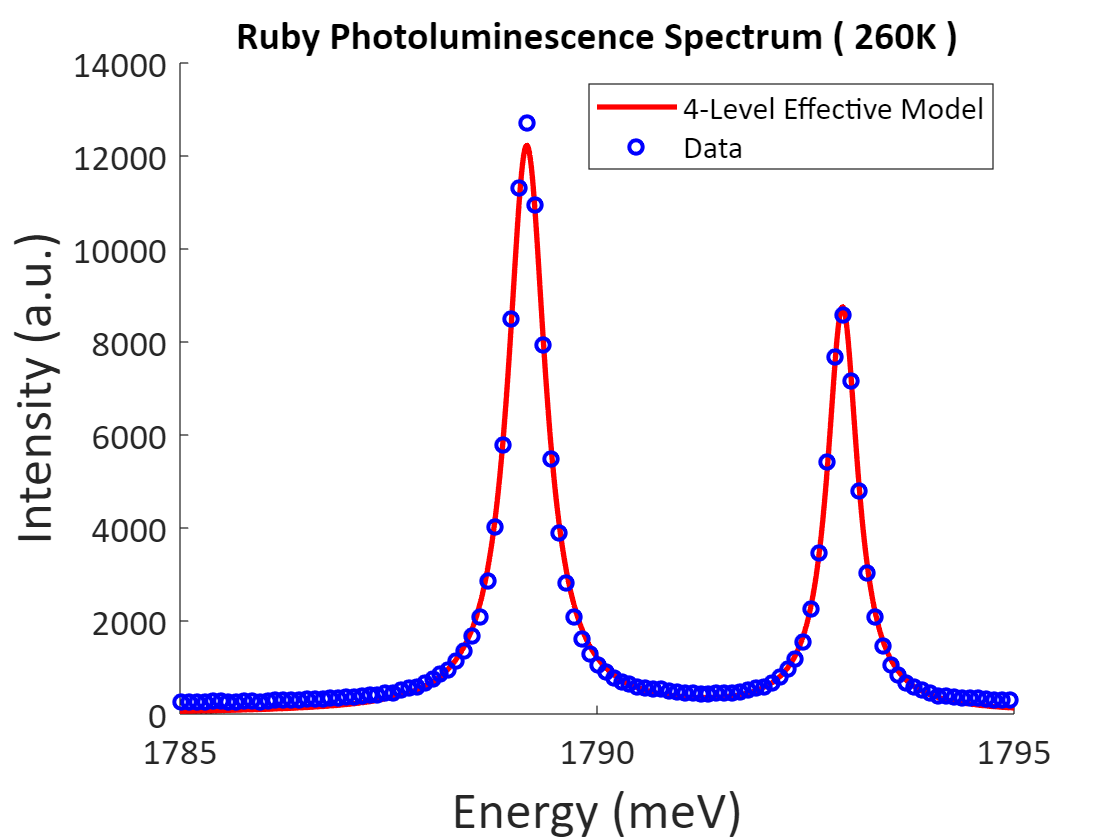

Fit Parameters :


T = 260 K


I0 = 3339


d_{20}/d_{10} = 0.83


Linewidths = [0.5472, 0.4467]


Delta = 3.786


E1 = 1789


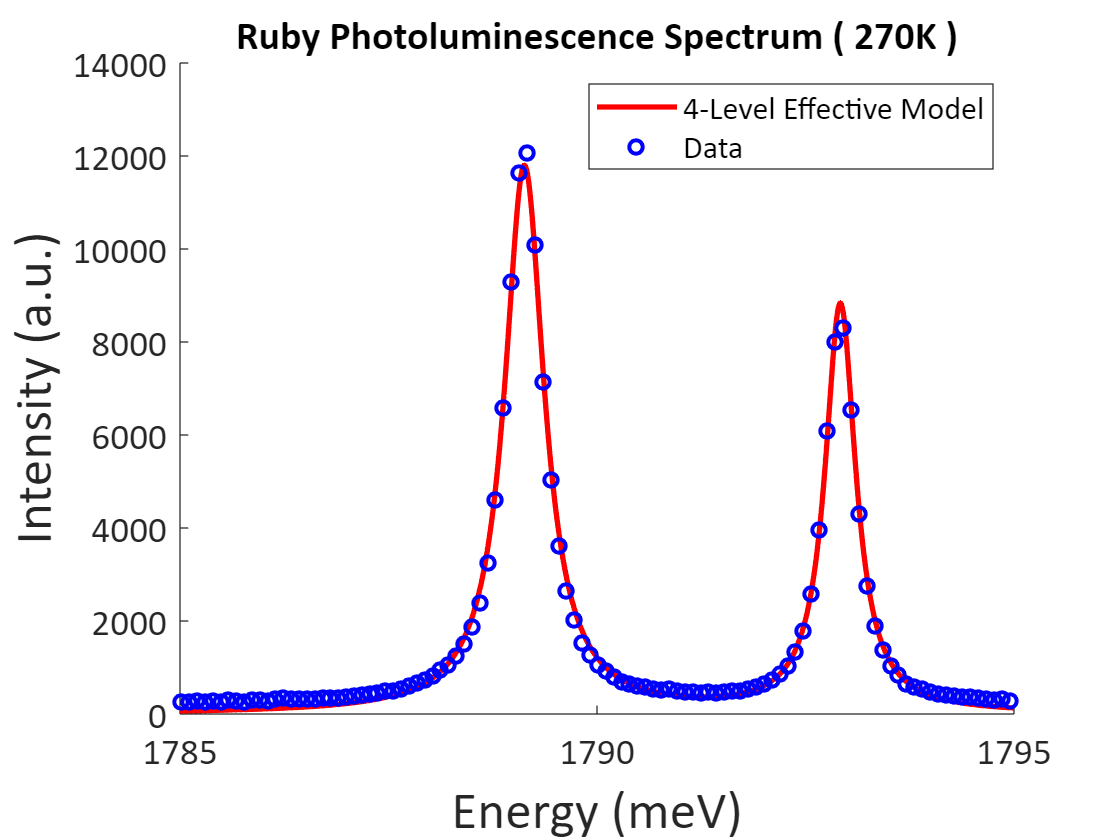

Fit Parameters :


T = 270 K


I0 = 3398


d_{20}/d_{10} = 0.8238


Linewidths = [0.5773, 0.4467]


Delta = 3.789


E1 = 1789


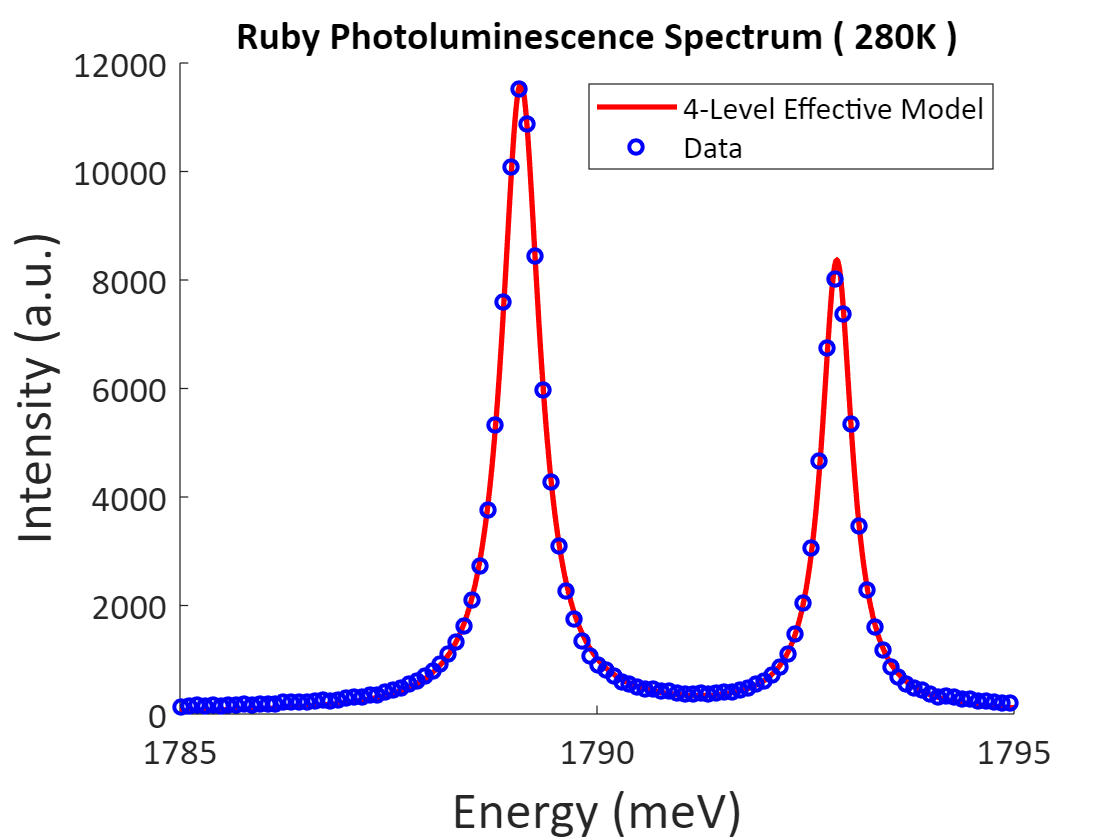

Fit Parameters :


T = 280 K


I0 = 3213


d_{20}/d_{10} = 0.8221


Linewidths = [0.554, 0.4467]


Delta = 3.79


E1 = 1789


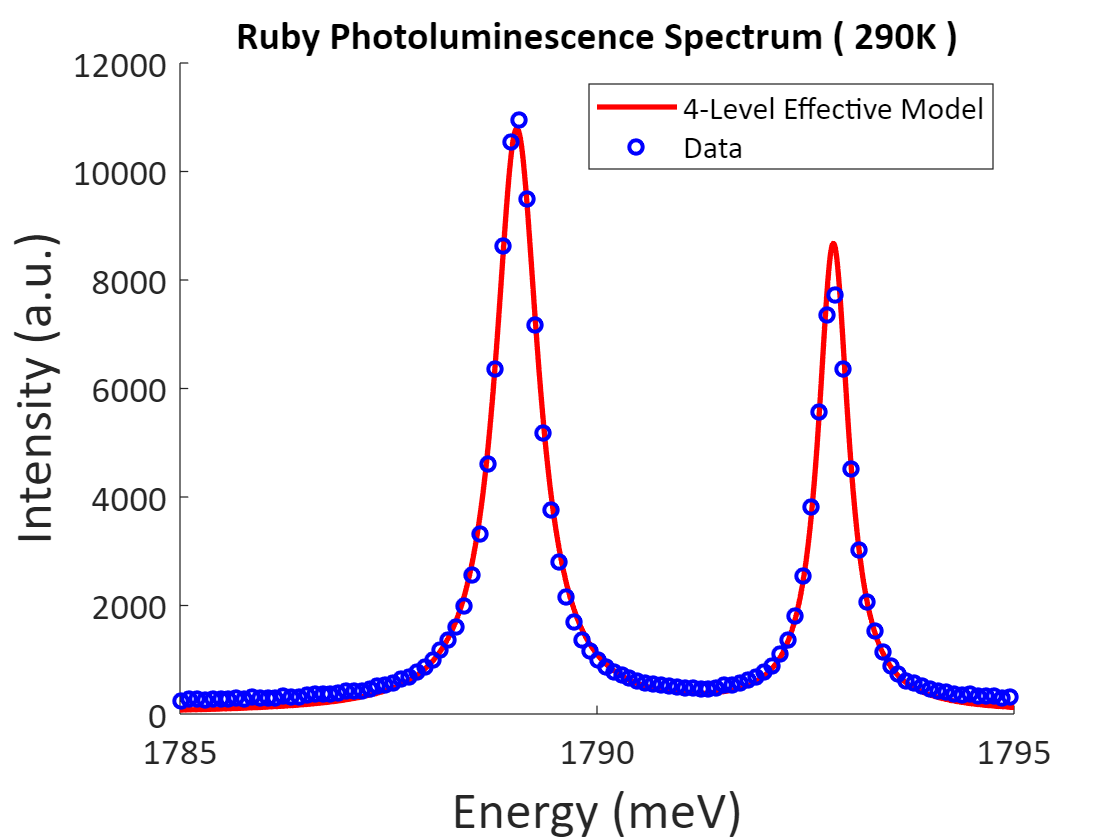

Fit Parameters :


T = 290 K


I0 = 3396


d_{20}/d_{10} = 0.8116


Linewidths = [0.631, 0.4467]


Delta = 3.795


E1 = 1789


for Dnum = 1:29
    
    T = 10*Dnum;    % temperature

    % choose data near the peaks
    Idx = RubyData{Dnum}(:,1) > Erange(1) & RubyData{Dnum}(:,1) < Erange(2);
    E_data = RubyData{Dnum}(Idx,1);
    I_data = RubyData{Dnum}(Idx,2);

    % plot
    figure;
    hold on;
    I_fit = Spec_4lev(I0(Dnum), TransAmpR(Dnum), Linewidth(Dnum,:), Delta(Dnum), E1(Dnum), T, Energy);
    plot(Energy, I_fit, 'color', 'red', 'LineWidth', 2);
    plot(E_data, I_data, 'o', 'color', 'blue', 'Markersize', 5, 'LineWidth', 1.5);
    ax = gca;
    ax.FontSize = 14;
    ax.FontName = 'Calibri';
    xlabel('Energy (meV)', 'FontName', 'Calibri', 'FontSize', 20);
    ylabel('Intensity (a.u.)', 'FontName', 'Calibri', 'FontSize', 20);
    title(['Ruby Photoluminescence Spectrum ( ', sprintf('%d', T), 'K )'], 'FontName', 'Calibri', 'FontSize', 15);
    legend({'4-Level Effective Model', 'Data'}, 'Location','northeast', 'FontName', 'Calibri', 'FontSize', 12);
    hold off;
    
    % show fit parameters
    disp('Fit Parameters :')
    disp(['T = ', sprintf('%d', T), ' K']);
    disp(['I0 = ', sprintf('%.4g', I0(Dnum))]);
    disp(['d_{20}/d_{10} = ', sprintf('%.4g', TransAmpR(Dnum))]);
    disp(['Linewidths = [', sprintf('%.4g', Linewidth(Dnum,1)), ', ', sprintf('%.4g', Linewidth(Dnum,2)) ']']);
    disp(['Delta = ', sprintf('%.4g', Delta(Dnum))]);
    disp(['E1 = ', sprintf('%.4g', E1(Dnum))]);
end

## Plot Ruby data in subplots

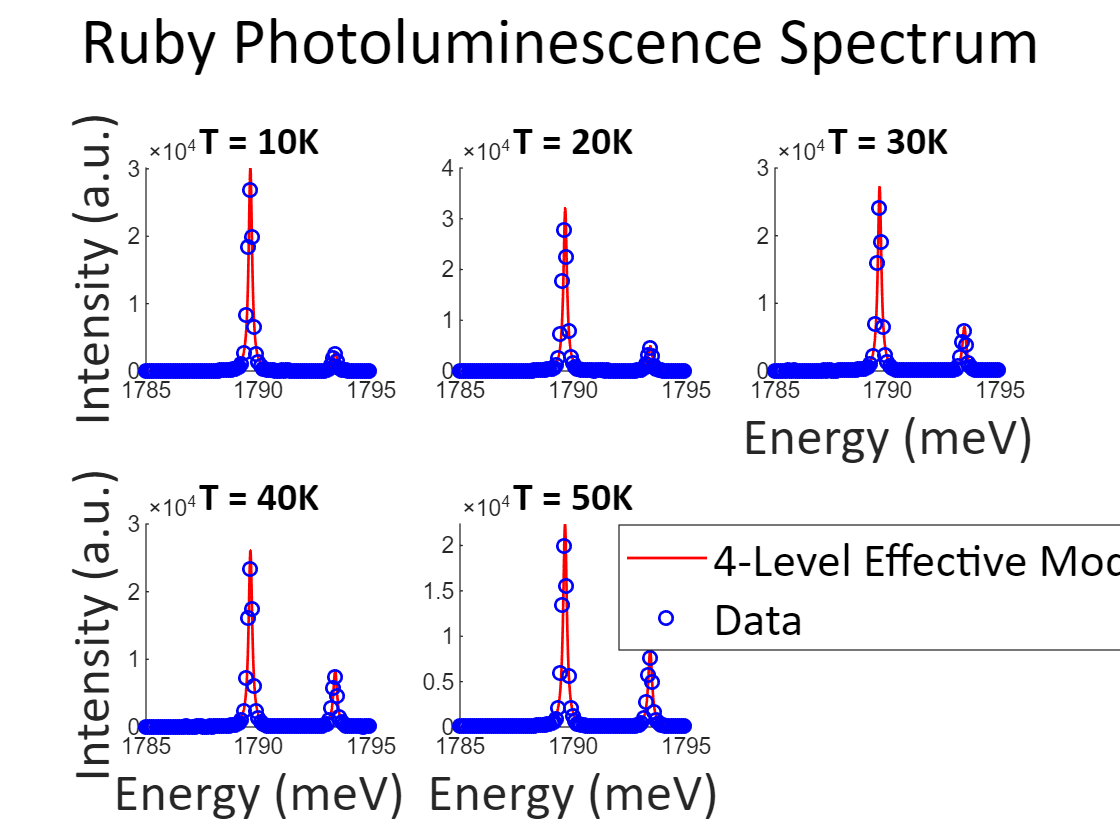

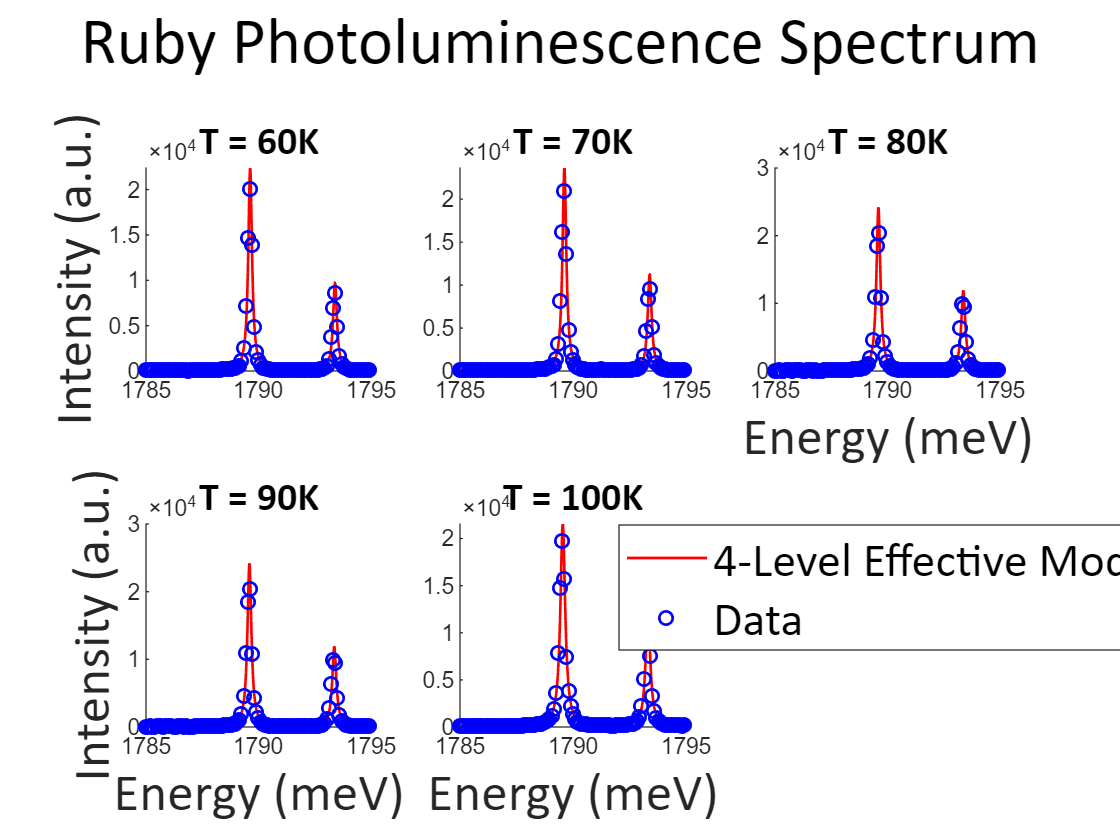

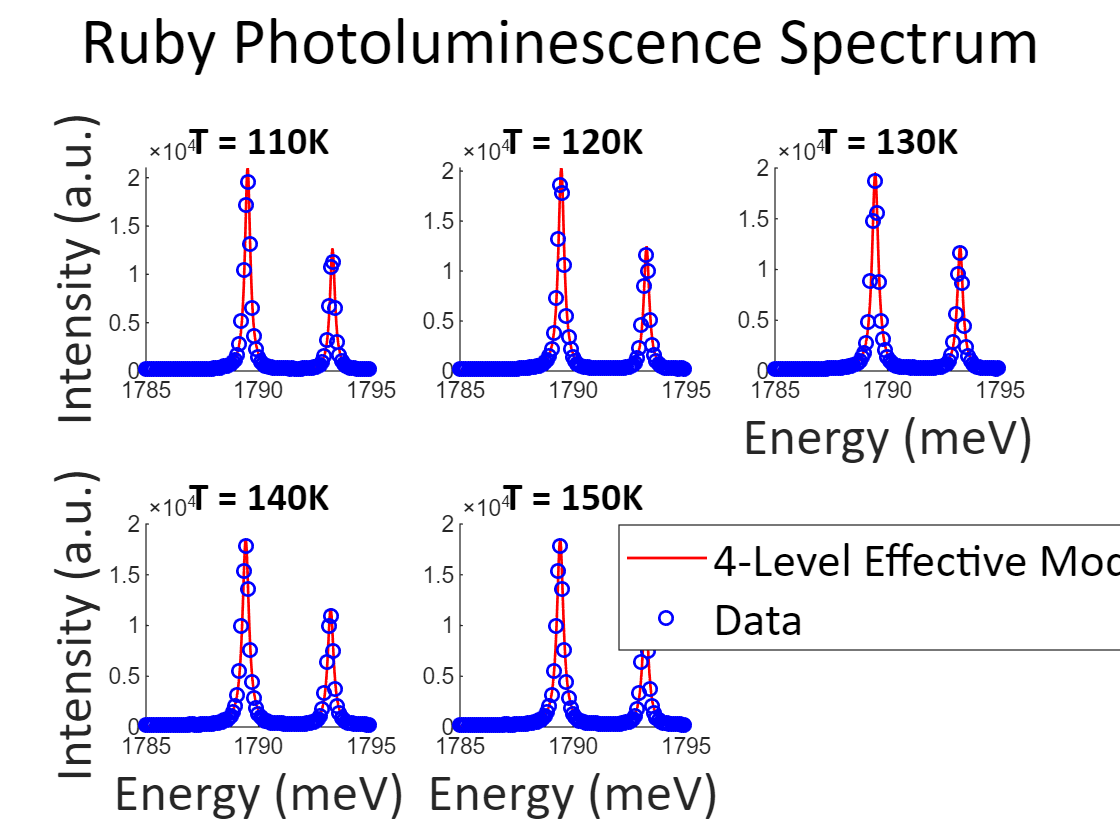

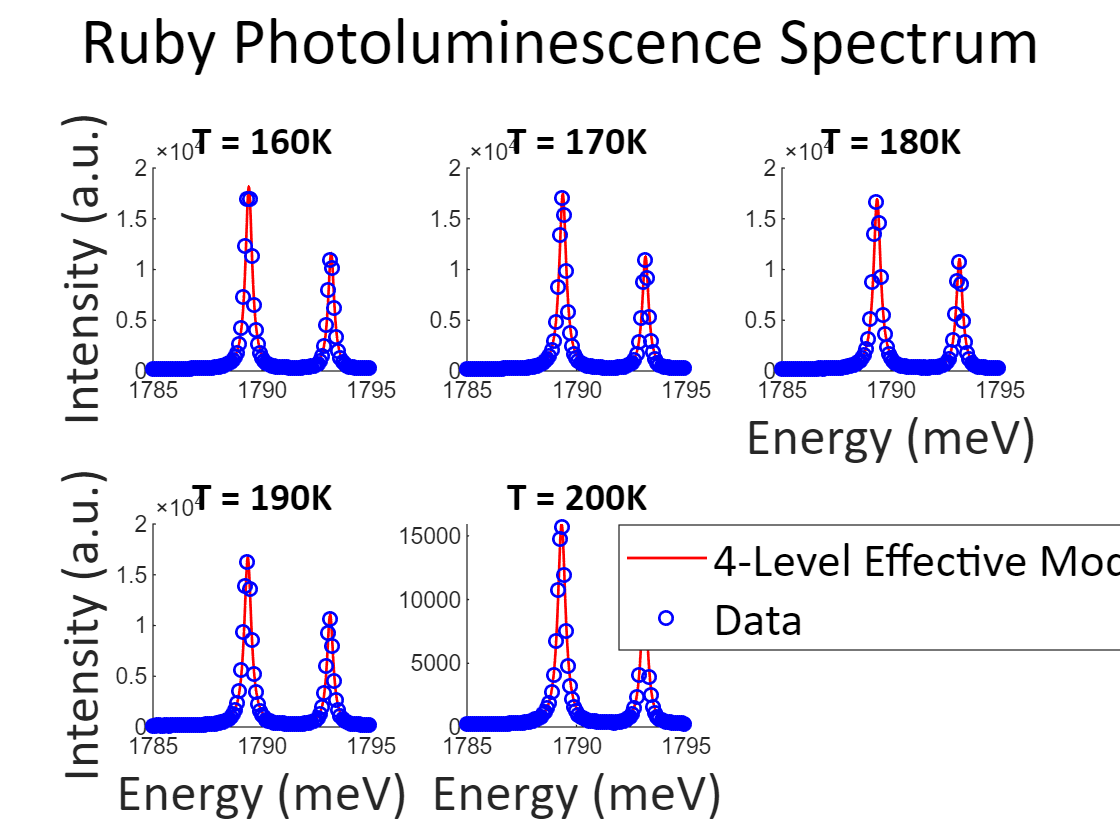

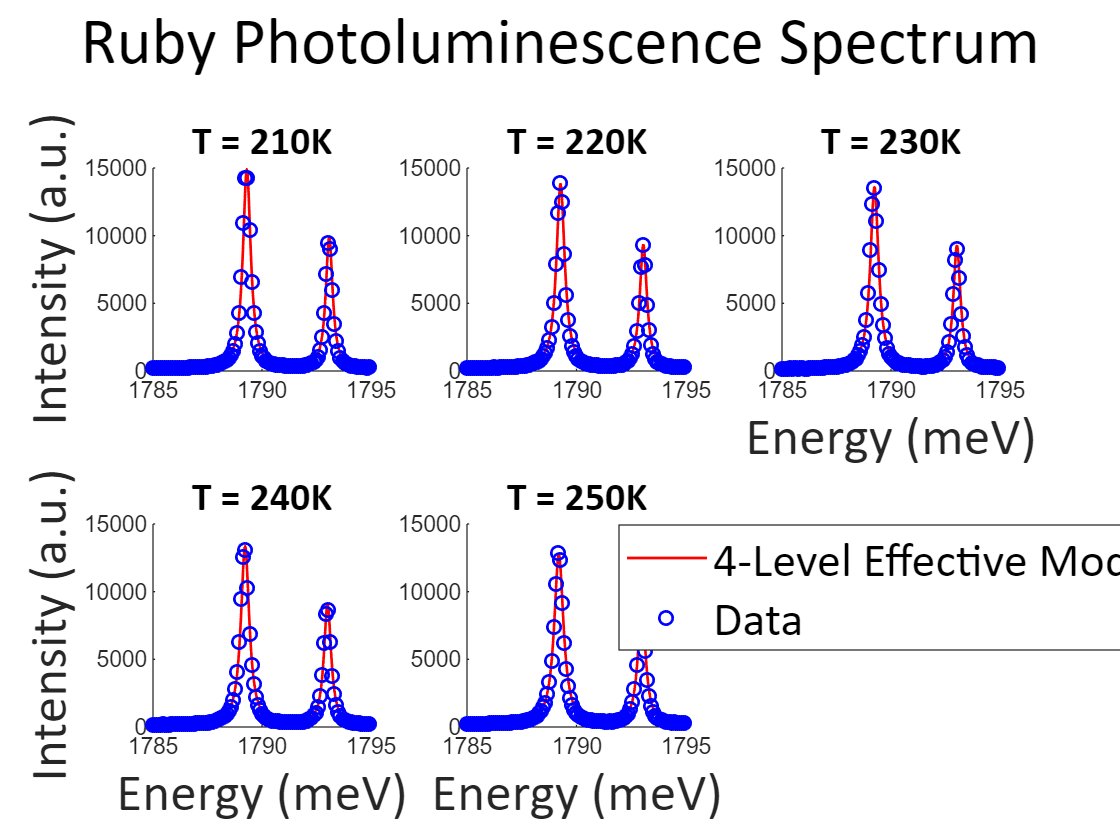

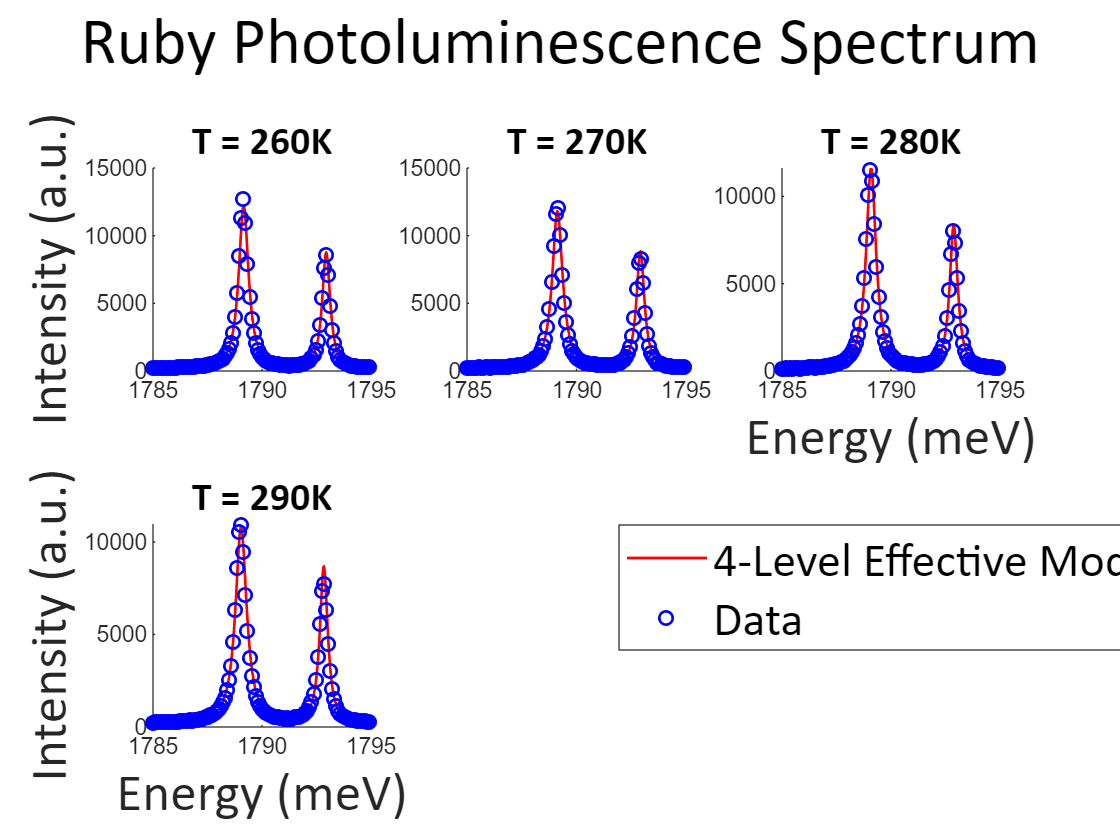

for itN = 0:5

    if itN == 5
        Snum = 4;
    else
        Snum = 5;
    end

    figure;
    hold on;
    sgtitle('Ruby Photoluminescence Spectrum', 'FontName', 'Calibri', 'FontSize', 25);

    for itS = 1:Snum
        Dnum = 5*itN + itS;
        T = 10*Dnum;
    
        % choose data near the peaks
        Idx = RubyData{Dnum}(:,1) > Erange(1) & RubyData{Dnum}(:,1) < Erange(2);
        E_data = RubyData{Dnum}(Idx,1);
        I_data = RubyData{Dnum}(Idx,2);
    
        % draw subplot
        ax = subplot(2,3,itS);
        hold on;
        title(['T = ', sprintf('%d', T), 'K'], 'FontName', 'Calibri','FontSize',15);
        I_fit = Spec_4lev(I0(Dnum), TransAmpR(Dnum), Linewidth(Dnum,:), Delta(Dnum), E1(Dnum), T, Energy);
        plot(Energy, I_fit, 'color', 'red', 'LineWidth', 1);
        plot(E_data, I_data, 'o', 'color', 'blue', 'Markersize', 5, 'LineWidth', 1);
        if itS > 2
            xlabel('Energy (meV)', 'FontName', 'Calibri', 'FontSize', 20);
        end
        if itS == 1 || itS ==4
            ylabel('Intensity (a.u.)', 'FontName', 'Calibri', 'FontSize', 20);
        end
        hold off;
    end

    hLeg = legend({'4-Level Effective Model', 'Data'}, 'Location','northeast', 'FontName', 'Calibri', 'FontSize', 18, 'location', 'Southeast');
    set(hLeg, 'Units', 'normalized');
    set(hLeg, 'Position', [0.75, 0.25 0.1 0.1]);  % Adjust as needed
    hold off;
end

## Fit Room Temperature Ruby Data at 7 Different Temperatures, to 4-level Effective Model

% photon energy range
Erange = [1785, 1795];
Energy = linspace(Erange(1), Erange(2), 1000);

% lower and upper bounds of fitting parameters
LowerBound = [500, 0.5, 0, 0, 3.5, 1785];
UpperBound = [3000, 3, 1, 1, 4, 1795];

% variables to store fit parameters
I0_R = zeros(7,1);
TransAmpR_R = zeros(7,1);
Linewidth_R = zeros(7,2);
Delta_R = zeros(7,1);
E1_R = zeros(7,1);

% try fitting for 7 different temperatures
for itN = 1:7

    T = 5*(itN+54);    % temperature
    
    % choose data near the peaks
    Idx = RubyRoomData(:,1) > Erange(1) & RubyRoomData(:,1) < Erange(2);
    E_data = RubyRoomData(Idx,1);
    I_data = RubyRoomData(Idx,2);
    
    % make parameter bounds and loss function into a single struct variable
    options.lb = LowerBound;
    options.ub = UpperBound;
    options.loss_type = loss_func;
    
    % define fitting curve
    FitModel = @(Params, Energies) Spec_4lev(Params(1), Params(2), [power(10, Params(3)), power(10, Params(4))], Params(5), Params(6), T, Energies);
    
    % iterate to find best fit
    best_loss = Inf;
    for it = 1:3
        options.rng_seed = it;          % Try different seeds
        Params0 = rand(1,6) .* (UpperBound - LowerBound) + LowerBound;      % try different initial parameters
        [params_i, loss_hist_i] = de_curve_fit(FitModel, E_data, I_data, Params0, options);     % differential evolution fitting
        if loss_hist_i(end) < best_loss
            best_loss = loss_hist_i(end);
            FitParams = params_i;
            loss_history = loss_hist_i;
        end
    end
    
    I0_R(itN) = FitParams(1);
    TransAmpR_R(itN) = FitParams(2);
    Linewidth_R(itN,:) = [power(10, FitParams(3)), power(10, FitParams(4))];
    Delta_R(itN) = FitParams(5);
    E1_R(itN) = FitParams(6);

    % show message
    disptime(['T = ', sprintf('%d', T), 'K | loss = ', sprintf('%.4g', best_loss)]);
end

## Plot Room Temperature Ruby Data with Fit Curve

for itN = 1:7

    T = 5*(itN+54);    % temperature
    
    % choose data near the peaks
    Idx = RubyRoomData(:,1) > Erange(1) & RubyRoomData(:,1) < Erange(2);
    E_data = RubyRoomData(Idx,1);
    I_data = RubyRoomData(Idx,2);

    % plot
    figure;
    hold on;
    I_fit = Spec_4lev(I0(itN), TransAmpR(itN), Linewidth(itN,:), Delta(itN), E1(itN), T, Energy);
    plot(Energy, I_fit, 'color', 'red', 'LineWidth', 2);
    plot(E_data, I_data, 'o', 'color', 'blue', 'LineWidth', 2);
    ax = gca;
    ax.FontSize = 14;
    ax.FontName = 'Calibri';
    xlabel('Energy (meV)', 'FontName', 'Calibri', 'FontSize', 20);
    ylabel('Intensity (a.u.)', 'FontName', 'Calibri', 'FontSize', 20);
    title(['Ruby Photoluminescence Spectrum at Room Temperature ( ', sprintf('%d', T), 'K )'], 'FontName', 'Calibri', 'FontSize', 14);
    legend({'4-Level Effective Model', 'Data'}, 'Location','northeast', 'FontName', 'Calibri', 'FontSize', 12);
    hold off;
    
    % show fit parameters
    disp('Fit Parameters :')
    disp(['T = ', sprintf('%d', T), ' K']);
    disp(['I0 = ', sprintf('%.4g', I0_R(itN))]);
    disp(['d_{20}/d_{10} = ', sprintf('%.4g', TransAmpR_R(itN))]);
    disp(['Linewidths = [', sprintf('%.4g', Linewidth_R(itN,1)), ', ', sprintf('%.4g', Linewidth_R(itN,2)) ']']);
    disp(['Delta = ', sprintf('%.4g', Delta_R(itN))]);
    disp(['E1 = ', sprintf('%.4g', E1_R(itN))]);
end